% load ryan4_data.mat
% load ryan4_model_First_RUL.mat

generate_model = true
% generate_model = false
if generate_model == false
    load ryan4_model_First_RUL.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

% IcFirstFull
load('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','x_test_IcFirstFull_RUL')
%load('ryan4_data.mat','xmin_IcFirstFull_RUL','xrate_IcFirstFull_RUL')
% IcFirst
load('ryan4_data.mat','x_trainValid_IcFirst_RUL','x_test_IcFirst_RUL')
load('ryan4_data.mat','xmin_IcFirst_RUL','xrate_IcFirst_RUL')
% VdFirstFull
load('ryan4_data.mat','x_trainValid_VdFirstFull_RUL','x_test_VdFirstFull_RUL')
%load('ryan4_data.mat','xmin_VdFirstFull_RUL','xrate_VdFirstFull_RUL')
% VdFirst
load('ryan4_data.mat','x_trainValid_VdFirst_RUL','x_test_VdFirst_RUL')
load('ryan4_data.mat','xmin_VdFirst_RUL','xrate_VdFirst_RUL')
% RUL First 
load('ryan4_data.mat','y_trainValid_First_RUL','y_test_First_RUL')
load('ryan4_data.mat','Y_trainValid_First_RUL','Y_test_First_RUL')
load('ryan4_data.mat','ymin_First_RUL','yrate_First_RUL')


% Ic / Vd 
load('ryan4_data.mat','x_trainValid_Ic_SOH','x_test_Ic_SOH')
load('ryan4_data.mat','x_trainValid_Vd_SOH','x_test_Vd_SOH')
load('ryan4_data.mat','xmin_Ic_SOH','xrate_Ic_SOH')
load('ryan4_data.mat','xmin_Vd_SOH','xrate_Vd_SOH')
% SOH  
load('ryan4_data.mat','y_trainValid_SOH','y_test_SOH')
load('ryan4_data.mat','Y_trainValid_SOH','Y_test_SOH')



# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html
% load('ryan4_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_IcFirst_RUL','y_trainValid_IcFirst_RUL')

if generate_model
mdl_Linear_IcFirstFull_Rul = fitlm(x_trainValid_IcFirstFull_RUL,y_trainValid_First_RUL)
mdl_Linear_IcFirst_Rul = fitlm(x_trainValid_IcFirst_RUL,y_trainValid_First_RUL)
mdl_Linear_VdFirstFull_Rul = fitlm(x_trainValid_VdFirstFull_RUL,y_trainValid_First_RUL)
mdl_Linear_VdFirst_Rul = fitlm(x_trainValid_VdFirst_RUL,y_trainValid_First_RUL)


ryan4_model_First_RUL_desc = "ryan4_model_First_RUL_desc"
%save('ryan4_model_First_RUL.mat','ryan4_model_First_RUL_desc' )
save('ryan4_model_First_RUL.mat','mdl_Linear_IcFirstFull_Rul' ,'-append')
save('ryan4_model_First_RUL.mat','mdl_Linear_IcFirst_Rul' ,'-append')
save('ryan4_model_First_RUL.mat','mdl_Linear_VdFirstFull_Rul' ,'-append')
save('ryan4_model_First_RUL.mat','mdl_Linear_VdFirst_Rul' ,'-append')
end

mdl_Linear_IcFirstFull_Rul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                   Estimate       SE         tStat       pValue 
                   _________    _______    _________    ________

    (Intercept)        17.75     18

mdl_Linear_IcFirst_Rul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)     0.66167    0.74069     0.89333       0.37418
    x1             -0.21049      0.305    -0.69013       0.49197
    x2              0.55854    0.52697      1.0599       0.29215
    x3              -1.2137    0.76796     -1.5804       0.11769
    x4              0.35143    0.72251      0.4864       0.62792
    x5              0.47563    0.83409     0.57024          0.57
    x6             -0.74467 

mdl_Linear_VdFirstFull_Rul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                   Estimate       SE         tStat       pValue 
                   _________    _______    _________    ________

    (Intercept)       24.025     12

mdl_Linear_VdFirst_Rul = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    ________    _________

    (Intercept)    -1.2423      4.7773    -0.26003      0.79546
    x1             -6.8065      24.973    -0.27256      0.78585
    x2              -116.8      113.65     -1.0277      0.30696
    x3              36.761      236.65     0.15534      0.87692
    x4              169.63      268.54     0.63167      0.52928
    x5              204.61      255.15     0.80191      0.42481
    x6             -628.48      324.

ryan4_model_linear_fnn_desc = "ryan4_model_linear_fnn"

# 선형회귀 - 예측 - IcFirstFull (100)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff_IcFirstFull = mdl_Linear_IcFirstFull_Rul.Coefficients.Estimate;
coeff_IcFirstFull'

ans = 	1.0e+03 *

    0.0178    0.0014   -0.0026    0.0034    0.5808   -0.5761    0.0563   -0.0626   -0.3389    0.3424   -0.3824    0.5670   -0.1883   -0.0007   -0.0017   -0.1979   -0.4867    0.6837   -0.0006    0.0345   -0.0305    0.7489   -0.7591    0.0091   -0.0002   -0.0023   -0.1155    0.1179    0.0020   -0.0027    0.6212   -0.6633    0.3050   -0.2633    0.0032    0.0186   -0.0206    0.0005    0.1448    0.2653   -0.9381    0.0891    0.5851   -0.1447   -0.2646    0.0361    0.2271   -0.2106    0.2751    0.4515


x_trainValid_IcFirstFull_RUL(1,:)

ans =     0.2497    0.2497    0.2497    0.2497    0.2497    0.2497    0.2498    0.2497    0.2498    0.7492    0.7492    0.7493    0.7493    0.7492    0.7492    0.7492    0.7492    0.7494    0.7491    0.7491    0.7491    0.7492    0.7490    0.7491    0.7493    0.7492    0.7491    0.7492    0.7493    0.7493    0.7492    0.7492    0.7492    0.7492    0.7493    0.7493    0.7492    0.7493    0.7494    0.7493    0.7493    0.7492    0.7493    0.7492    0.7492    0.7492    0.7493    0.7493    0.7433    0.7348


yhat_trainValid_IcFirstFull = x_trainValid_IcFirstFull_RUL*coeff_IcFirstFull(2:101)+coeff_IcFirstFull(1);
yhat_trainValid_IcFirstFull'

ans =     0.0000    0.0057    0.0016    0.0189    0.0067    0.0139    0.0392   -0.0475    0.0299    0.0415    0.0431    0.0451    0.1226    0.0647    0.0094    0.0702    0.0706    0.0726    0.0802    0.0997    0.1007    0.0900    0.0938    0.0936    0.1022    0.1006    0.0962    0.0981    0.1076    0.0609    0.0454    0.1061    0.0790    0.1238    0.1269    0.1172    0.1343    0.1273    0.1370    0.1332    0.1494    0.2031    0.1510    0.1487    0.2748    0.1884    0.2506    0.0926    0.1773    0.3745


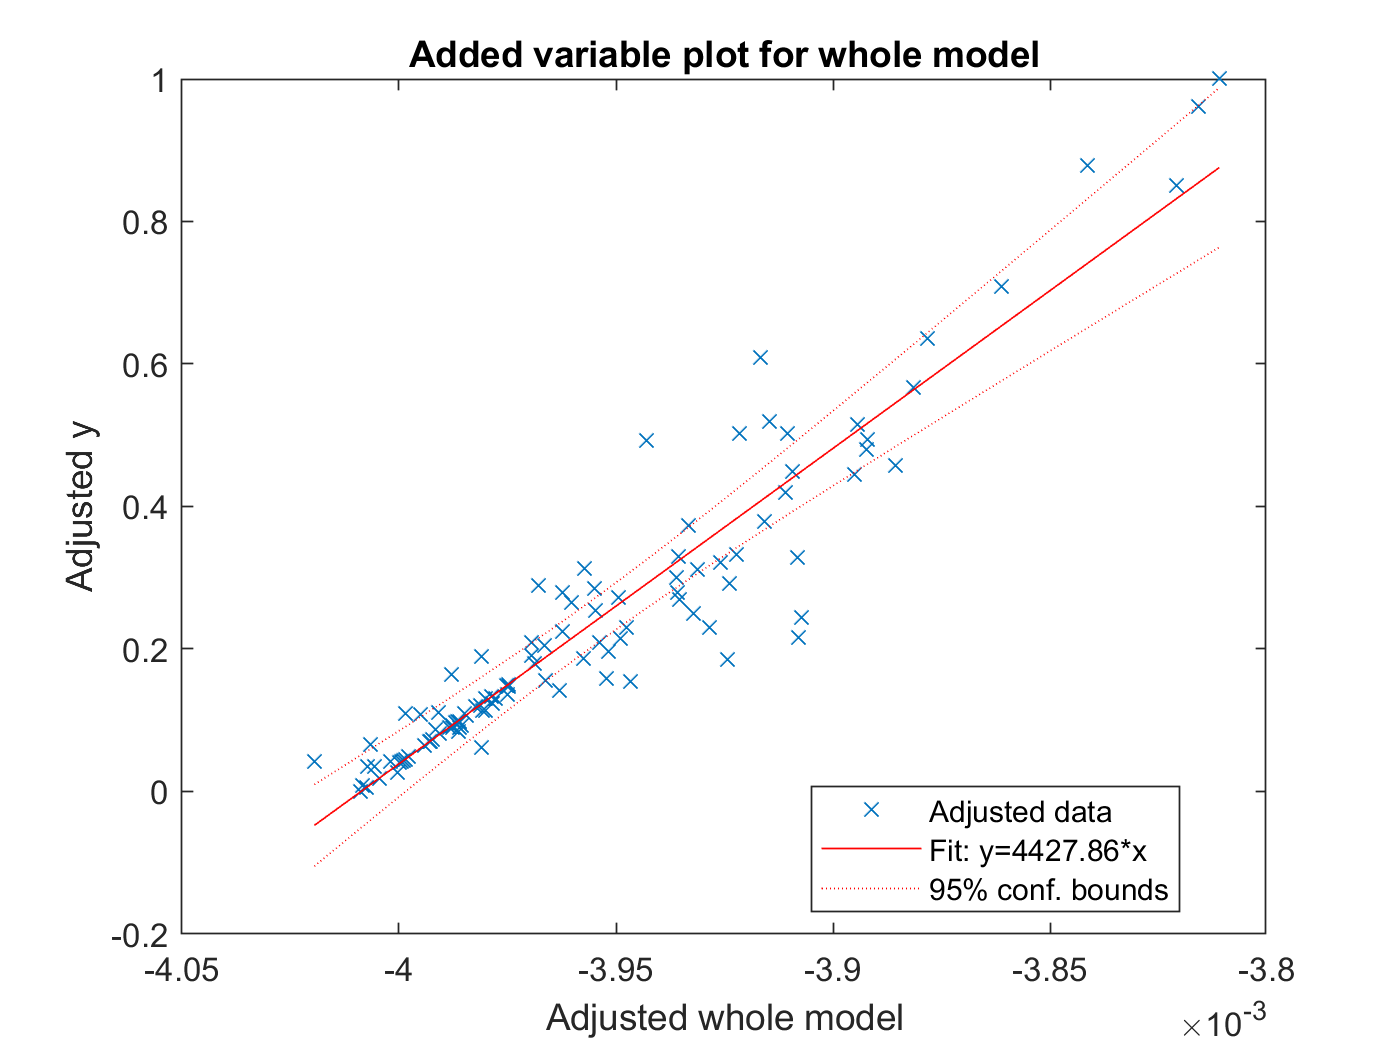



% figure
% hold on
% plot(y_trainValid_First_RUL,yhat_trainValid_IcFirstFull,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'
%capHat = Ic(1)
figure
plot(mdl_Linear_IcFirstFull_Rul)

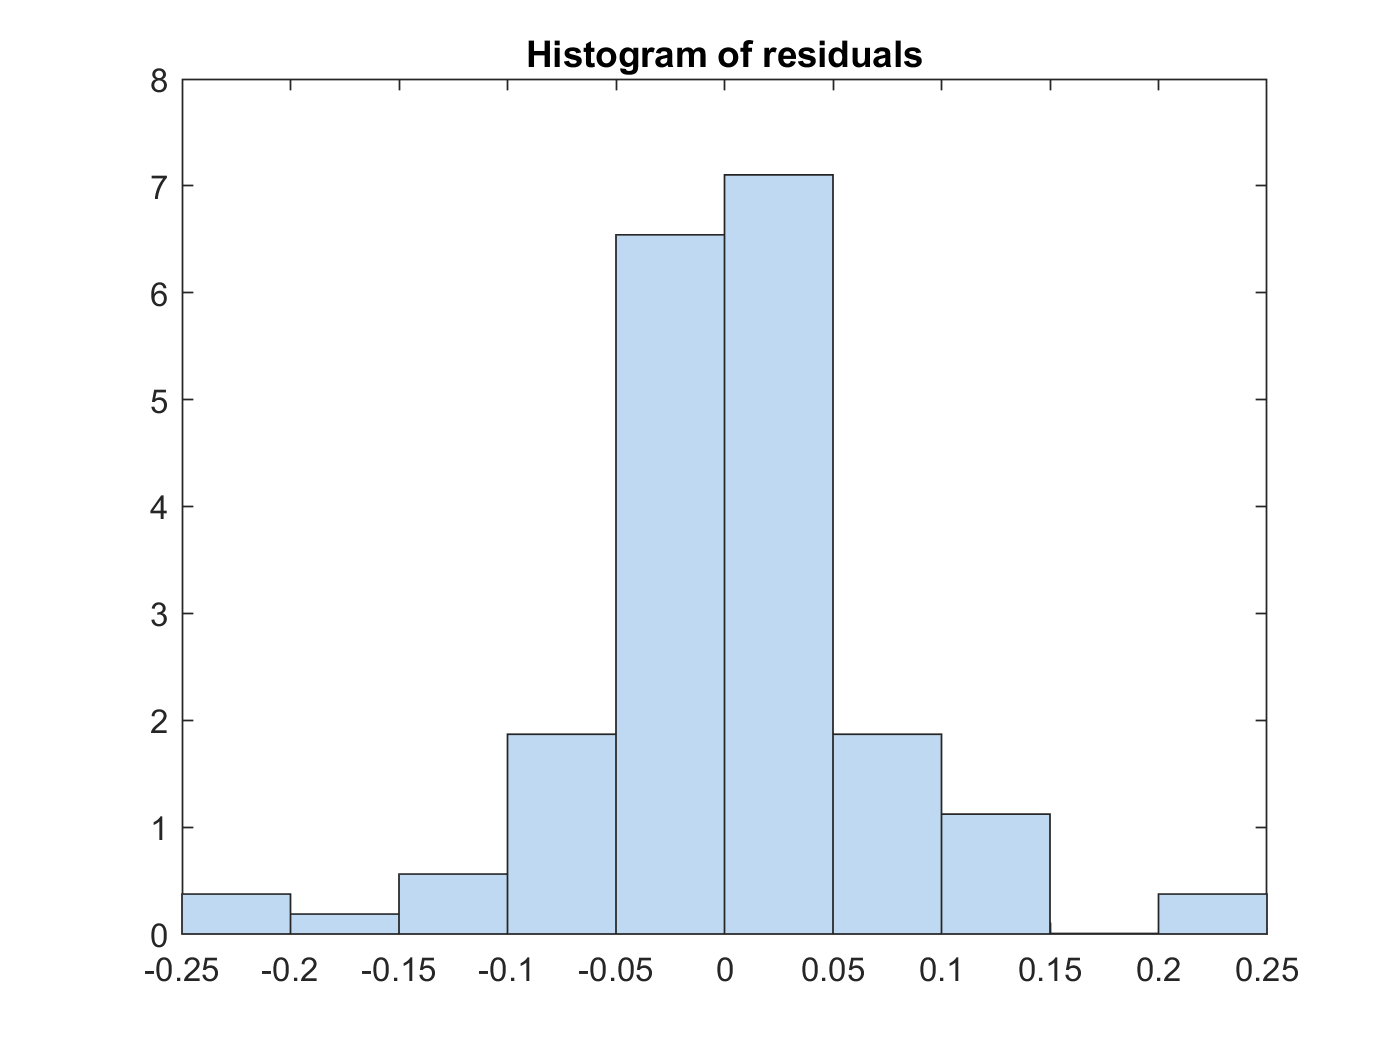

plotResiduals(mdl_Linear_IcFirstFull_Rul)

figure
yfit_trainValid_IcFirstFull = predict(mdl_Linear_IcFirstFull_Rul,x_trainValid_IcFirstFull_RUL);
yfit_trainValid_IcFirstFull'

ans =     0.0000    0.0057    0.0016    0.0189    0.0067    0.0139    0.0392   -0.0475    0.0299    0.0415    0.0431    0.0451    0.1226    0.0647    0.0094    0.0702    0.0706    0.0726    0.0802    0.0997    0.1007    0.0900    0.0938    0.0936    0.1022    0.1006    0.0962    0.0981    0.1076    0.0609    0.0454    0.1061    0.0790    0.1238    0.1269    0.1172    0.1343    0.1273    0.1370    0.1332    0.1494    0.2031    0.1510    0.1487    0.2748    0.1884    0.2506    0.0926    0.1773    0.3745


yfit_test_IcFirstFull = predict(mdl_Linear_IcFirstFull_Rul,x_test_IcFirstFull_RUL);
yfit_test_IcFirstFull'

ans =    -0.2164   -0.2213  -34.0543    0.2739   -0.5006   -3.8682    0.0524    0.6611    0.4190    0.5522    0.5316    0.6073



y_trainValid_First_RUL'

ans =          0    0.0056    0.0085    0.0188    0.0348    0.0348    0.0405    0.0414    0.0414    0.0424    0.0433    0.0452    0.0612    0.0650    0.0659    0.0706    0.0706    0.0725    0.0819    0.0847    0.0895    0.0895    0.0895    0.0932    0.0932    0.0970    0.0970    0.0979    0.1073    0.1083    0.1092    0.1102    0.1111    0.1130    0.1130    0.1186    0.1234    0.1299    0.1309    0.1337    0.1356    0.1422    0.1469    0.1488    0.1544    0.1563    0.1591    0.1648    0.1798    0.1855


y_test_First_RUL'

ans =     0.0292    0.0556    0.0885    0.1064    0.1224    0.1516    0.1949    0.2316    0.2872    0.3719    0.4981    0.8569


# denormaize


Yfit_trainValid_IcFirstFull = yfit_trainValid_IcFirstFull * yrate_First_RUL + ymin_First_RUL;
Yfit_test_IcFirstFull = yfit_test_IcFirstFull * yrate_First_RUL + ymin_First_RUL;
%Y_test_First_RUL = y_test_IcFirst_RUL * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
Yhat_trainValid_IcFirstFull = yhat_trainValid_IcFirstFull * yrate_First_RUL + ymin_First_RUL;

MAE_IcFirstFull = mean(abs(Yfit_trainValid_IcFirstFull-Y_trainValid_First_RUL))

MAE_IcFirstFull = 44.6129

adjMAE_IcFirstFull = MAE_IcFirstFull/range(Y_trainValid_First_RUL)

adjMAE_IcFirstFull = 0.0420

range(Y_trainValid_First_RUL) % Y_trainValid_First_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(Y_trainValid_First_RUL - Yhat_trainValid_IcFirstFull)'    % Errors

ans =    -0.0059   -0.0669    7.3538   -0.0389   29.9009   22.2042    1.3510   94.4577   12.2838    0.9070    0.2030    0.0579  -65.2527    0.2693   60.0491    0.4185    0.0062   -0.1203    1.7857  -15.8478  -11.9576   -0.5672   -4.6205   -0.4355   -9.4958   -3.8213    0.8107   -0.2180   -0.2509   50.3112   67.7892    4.2988   34.0530  -11.4743  -14.7507    1.5298  -11.5814    2.7894   -6.4869    0.5444  -14.6800  -64.6448   -4.3748    0.0823 -127.8849  -34.1290  -97.1760   76.6605    2.7078 -200.6826


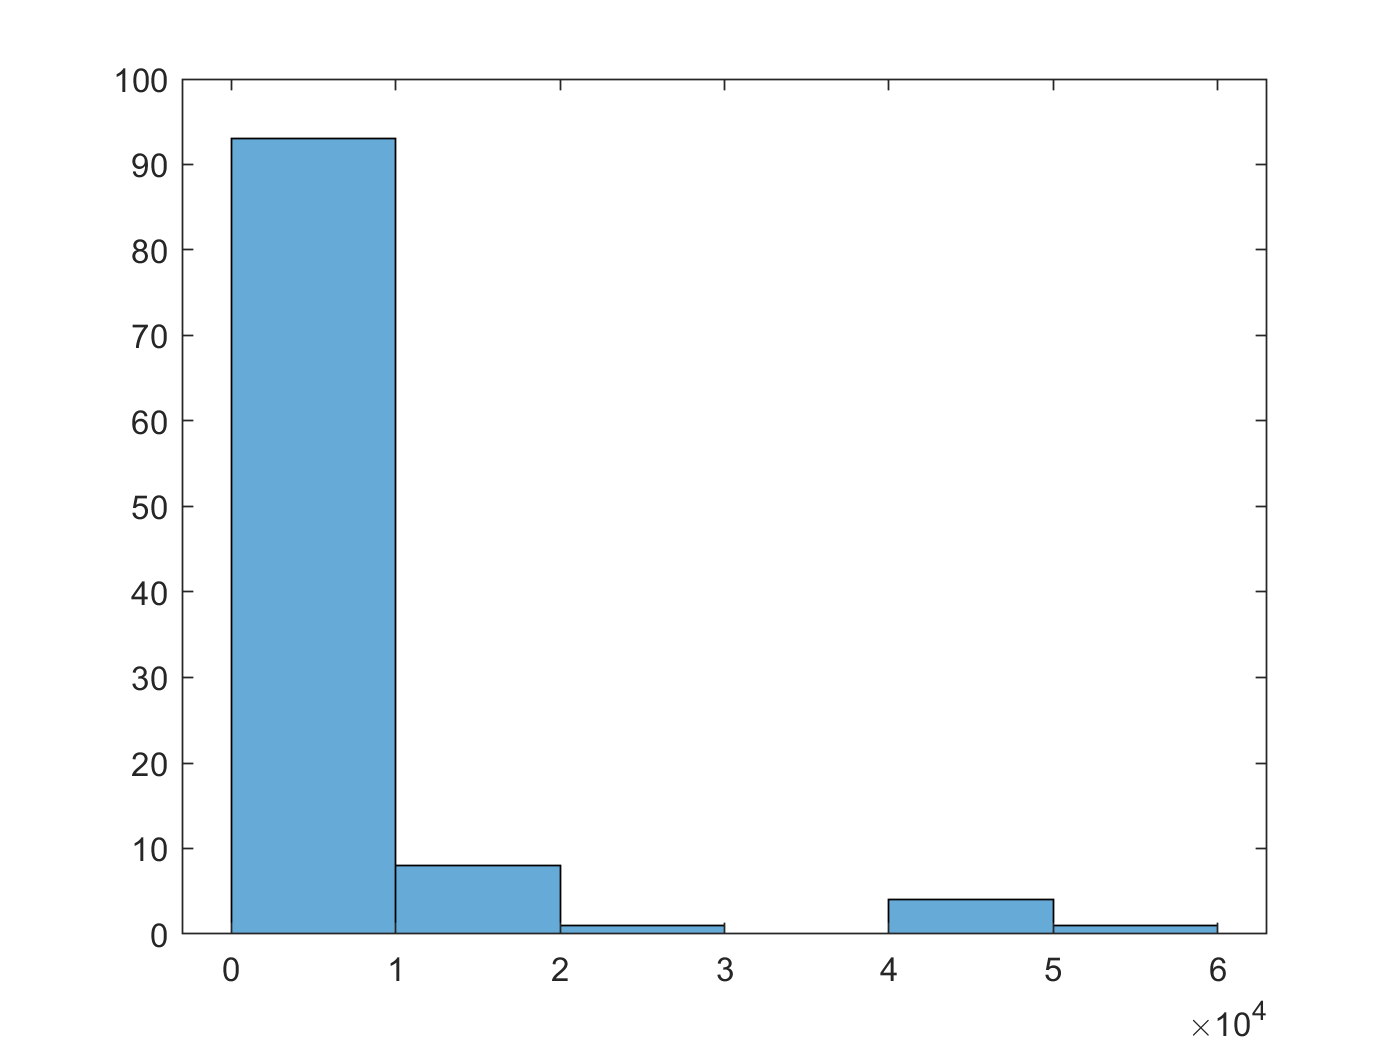

(Y_trainValid_First_RUL - Yhat_trainValid_IcFirstFull).^2;   % Squared Error
histogram((Y_trainValid_First_RUL - Yhat_trainValid_IcFirstFull).^2)

mean((Y_trainValid_First_RUL - Yhat_trainValid_IcFirstFull).^2);   % Mean Squared Error
RMSE_trainValid_IcFirstFull = sqrt(mean((Y_trainValid_First_RUL - Yhat_trainValid_IcFirstFull).^2))  % Root Mean Squared Error

RMSE_trainValid_IcFirstFull = 70.2073


RMSE_test_IcFirstFull = sqrt(mean((Y_test_First_RUL - Yfit_test_IcFirstFull).^2))

RMSE_test_IcFirstFull = 1.0543e+04

Y_test_First_RUL - Yfit_test_IcFirstFull

ans = 	1.0e+04 *

    0.0261
    0.0294
    3.6260
   -0.0178
    0.0662
    0.4269
    0.0151
   -0.0456
   -0.0140
   -0.0191


Y_test_diff_IcFirstFull = horzcat(Y_test_First_RUL,(Y_test_First_RUL-Yfit_test_IcFirstFull))

Y_test_diff_IcFirstFull = 	1.0e+04 *

    0.0140    0.0261
    0.0168    0.0294
    0.0203    3.6260
    0.0222   -0.0178
    0.0239    0.0662
    0.0270    0.4269
    0.0316    0.0151
    0.0355   -0.0456
    0.0414   -0.0140
    0.0504   -0.0191


Y_test_diff_percentage_IcFirstFull = abs(Y_test_First_RUL-Yfit_test_IcFirstFull)./Y_test_First_RUL.*100

Y_test_diff_percentage_IcFirstFull = 	1.0e+04 *

    0.0186
    0.0175
    1.7862
    0.0080
    0.0277
    0.1581
    0.0048
    0.0128
    0.0034
    0.0038


Y_test_diff_percentage_avg_IcFirstFull = sum(Y_test_diff_percentage_IcFirstFull)/length(Y_test_diff_percentage_IcFirstFull)

Y_test_diff_percentage_avg_IcFirstFull = 1.7034e+03

Y_trainValid_diff_IcFirstFull = horzcat(Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirstFull))

Y_trainValid_diff_IcFirstFull = 	1.0e+03 *

    0.1090   -0.0000
    0.1150   -0.0001
    0.1180    0.0074
    0.1290   -0.0000
    0.1460    0.0299
    0.1460    0.0222
    0.1520    0.0014
    0.1530    0.0945
    0.1530    0.0123
    0.1540    0.0009


Y_trainValid_diff_percentage_IcFirstFull = abs(Y_trainValid_First_RUL-Yfit_trainValid_IcFirstFull)./Y_trainValid_First_RUL.*100

Y_trainValid_diff_percentage_IcFirstFull =     0.0054
    0.0582
    6.2321
    0.0302
   20.4801
   15.2083
    0.8888
   61.7371
    8.0286
    0.5890


Y_trainValid_diff_percentage_avg_IcFirstFull = sum(Y_trainValid_diff_percentage_IcFirstFull)/length(Y_trainValid_diff_percentage_IcFirstFull)

Y_trainValid_diff_percentage_avg_IcFirstFull = 11.9776

num = 1:length(Y_trainValid_First_RUL);


result = horzcat(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirstFull),Y_trainValid_diff_percentage_IcFirstFull);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 	1.0e+03 *

    0.0010    0.1090   -0.0000    0.0000
    0.0020    0.1150   -0.0001    0.0001
    0.0030    0.1180    0.0074    0.0062
    0.0040    0.1290   -0.0000    0.0000
    0.0050    0.1460    0.0299    0.0205
    0.0060    0.1460    0.0222    0.0152
    0.0070    0.1520    0.0014    0.0009
    0.0080    0.1530    0.0945    0.0617
    0.0090    0.1530    0.0123    0.0080
    0.0100    0.1540    0.0009    0.0006


result_IcFirstFull = table(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirstFull),Y_trainValid_diff_percentage_IcFirstFull);
result_IcFirstFull.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_IcFirstFull

result_IcFirstFull = 107×4 table
    bat num    RUL       오차        오차비율 
    _______    ___    __________    _________

       1       109    -0.0058927    0.0054061
       2       115     -0.066918      0.05819
       3       118        7.3538       6.2321
       4       129     -0.038902     0.030157
       5       146        29.901        20.48
       6       146        22.204       15.208
       7       152         1.351      0.88885
       8       153        94.458       61.737
       9       153        12.284       8.0286
      10       154       0.90705      0.58899
      11       155       0.20303      0.13099
      12       157      0.057864     0.036856
      13       174       -65.253       37.502
      14       178       0.26935      0.15132
      15       179        60.049       33.547
      16       184       0.41848      0.22744


result_IcFirstFull_summary = table(RMSE_test_IcFirstFull,Y_trainValid_diff_percentage_avg_IcFirstFull);
result_IcFirstFull_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_IcFirstFull_summary 

result_IcFirstFull_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    10543      11.978  


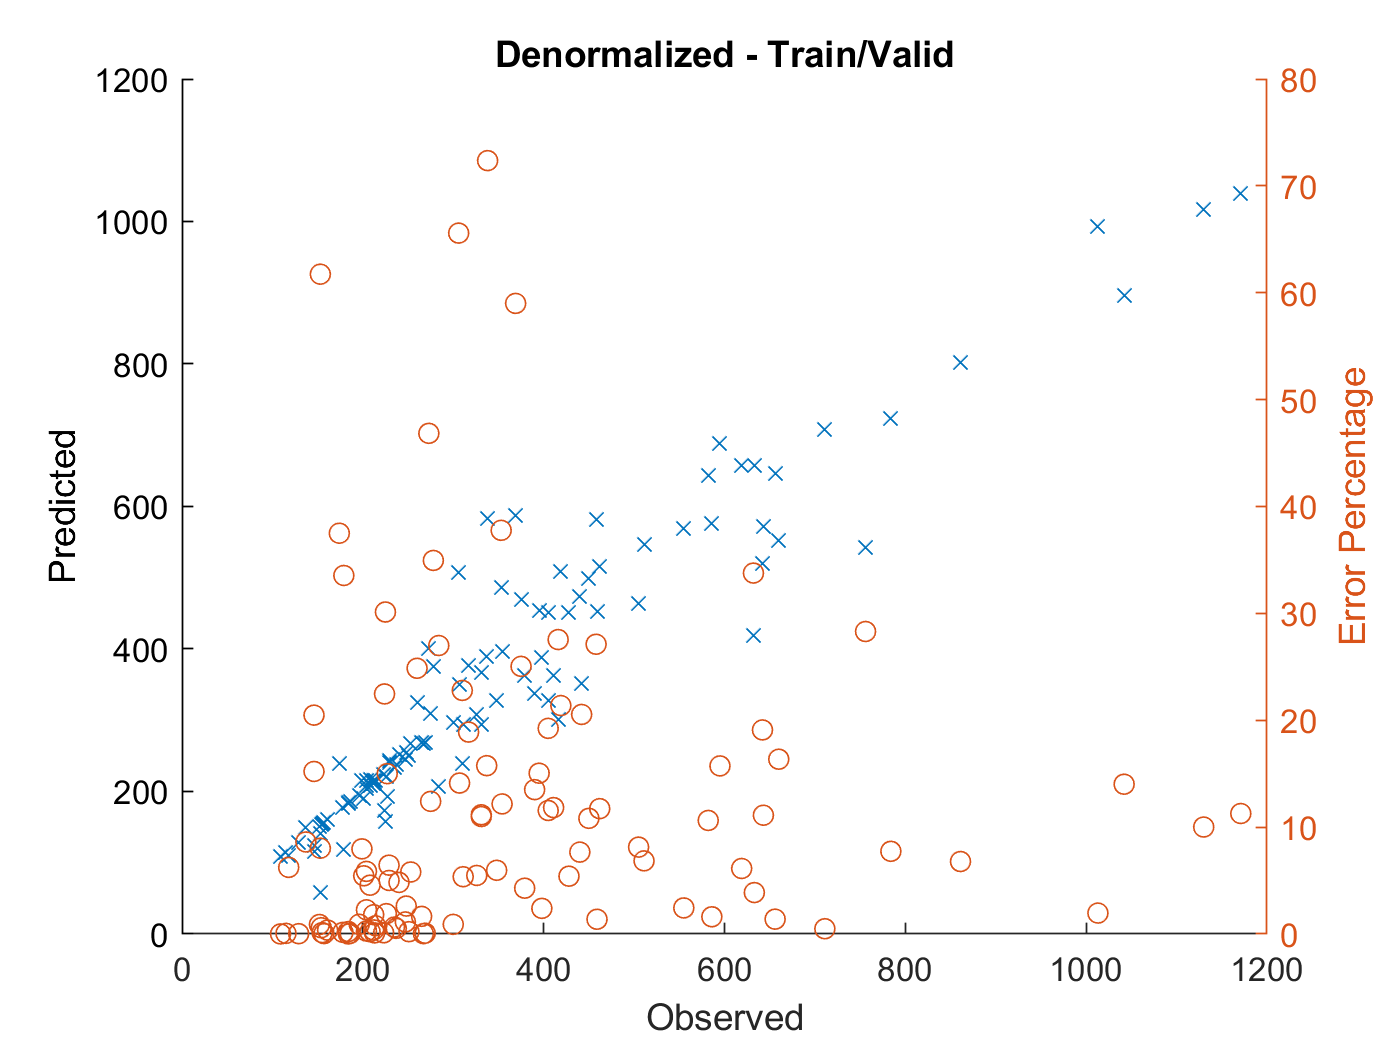


figure
hold on
plot(Y_trainValid_First_RUL,Yfit_trainValid_IcFirstFull,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_First_RUL,Y_trainValid_diff_percentage_IcFirstFull,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcFirstFull

RMSE_test_IcFirstFull = 1.0543e+04

Y_trainValid_diff_percentage_avg_IcFirstFull

Y_trainValid_diff_percentage_avg_IcFirstFull = 11.9776

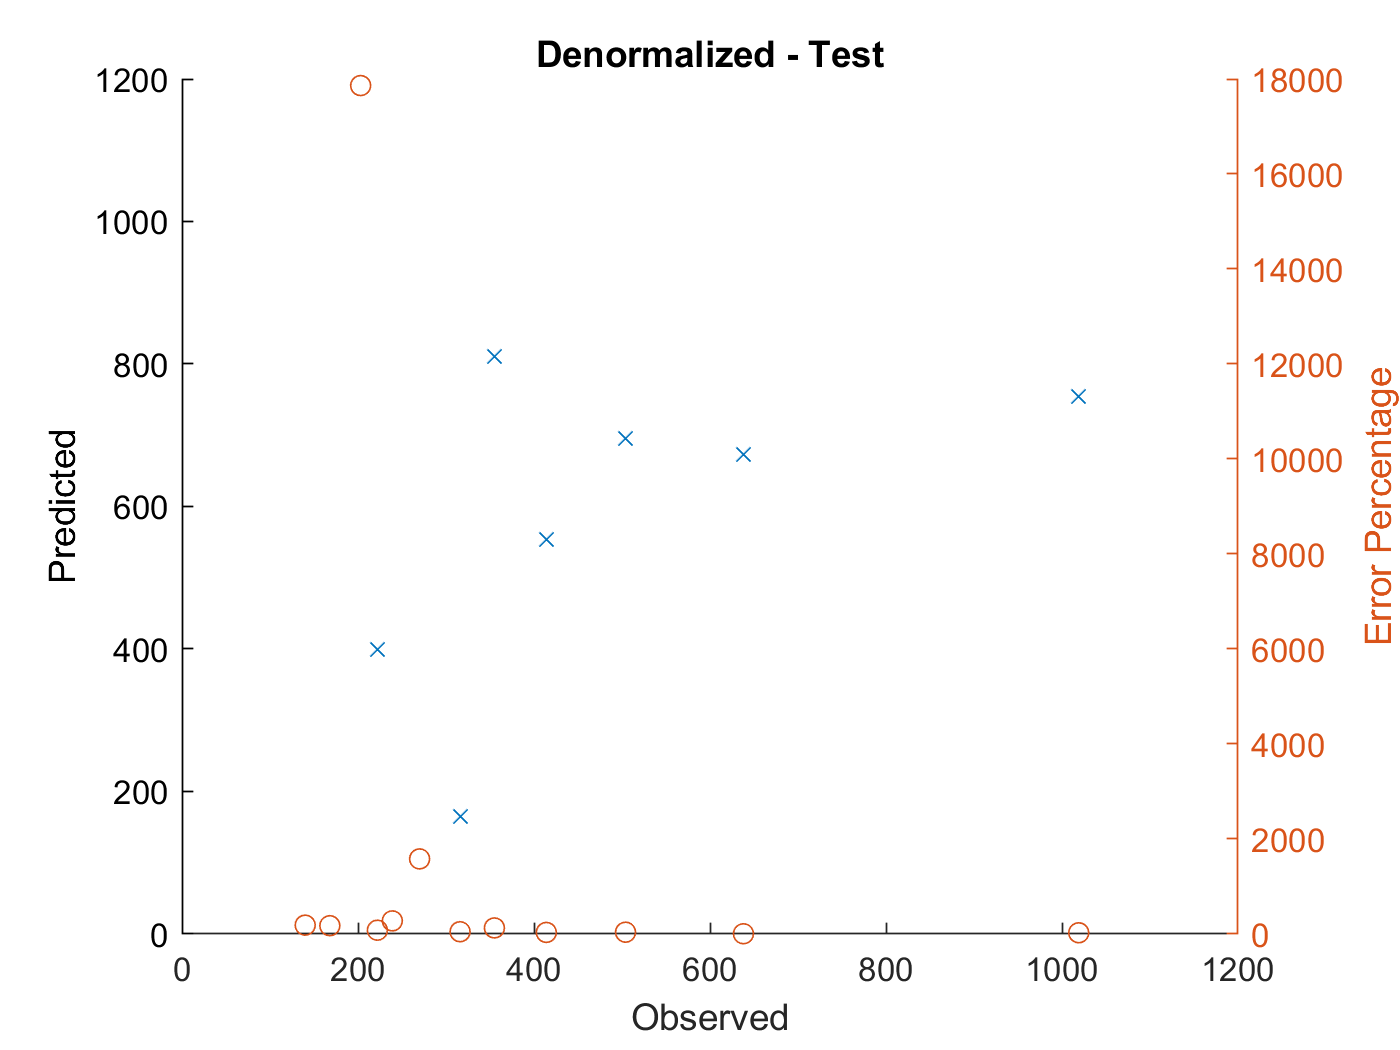


figure
hold on
plot(Y_test_First_RUL,Yfit_test_IcFirstFull,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_First_RUL,Y_test_diff_percentage_IcFirstFull,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - IcFirst (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff_IcFirst = mdl_Linear_IcFirst_Rul.Coefficients.Estimate;
coeff_IcFirst'

ans =     0.6617   -0.2105    0.5585   -1.2137    0.3514    0.4756   -0.7447    0.1139    0.4597   -0.2690   -0.1589    0.2532    0.1258   -0.2280   -0.2963    0.3533    2.1194   -6.1289   13.7901         0         0


x_trainValid_IcFirst_RUL(1,:)

ans =     0.2497    0.3496    0.7492    0.7492    0.7491    0.7492    0.7492    0.7493    0.7492    0.7452    0.7152    0.6896    0.6650    0.6342    0.4900    0.1249    0.1158    0.0159         0         0


yhat_trainValid_IcFirst = x_trainValid_IcFirst_RUL*coeff_IcFirst(2:21)+coeff_IcFirst(1);
yhat_trainValid_IcFirst'

ans =    -0.0574    0.1014    0.1239    0.0699    0.1620    0.0488    0.1540    0.1815    0.1356    0.1161    0.1471    0.0483    0.1579    0.1526    0.0297   -0.0355    0.1272    0.1768    0.1084    0.1116    0.0536    0.1188    0.0855    0.1235    0.0612    0.0765    0.1199    0.1368    0.0479    0.1440    0.1420    0.1259    0.1473    0.1858    0.1205    0.2251    0.0887    0.1865    0.1476    0.1624    0.1827    0.1381    0.1289    0.2117    0.4586    0.1608    0.2716    0.1707    0.1568    0.3785


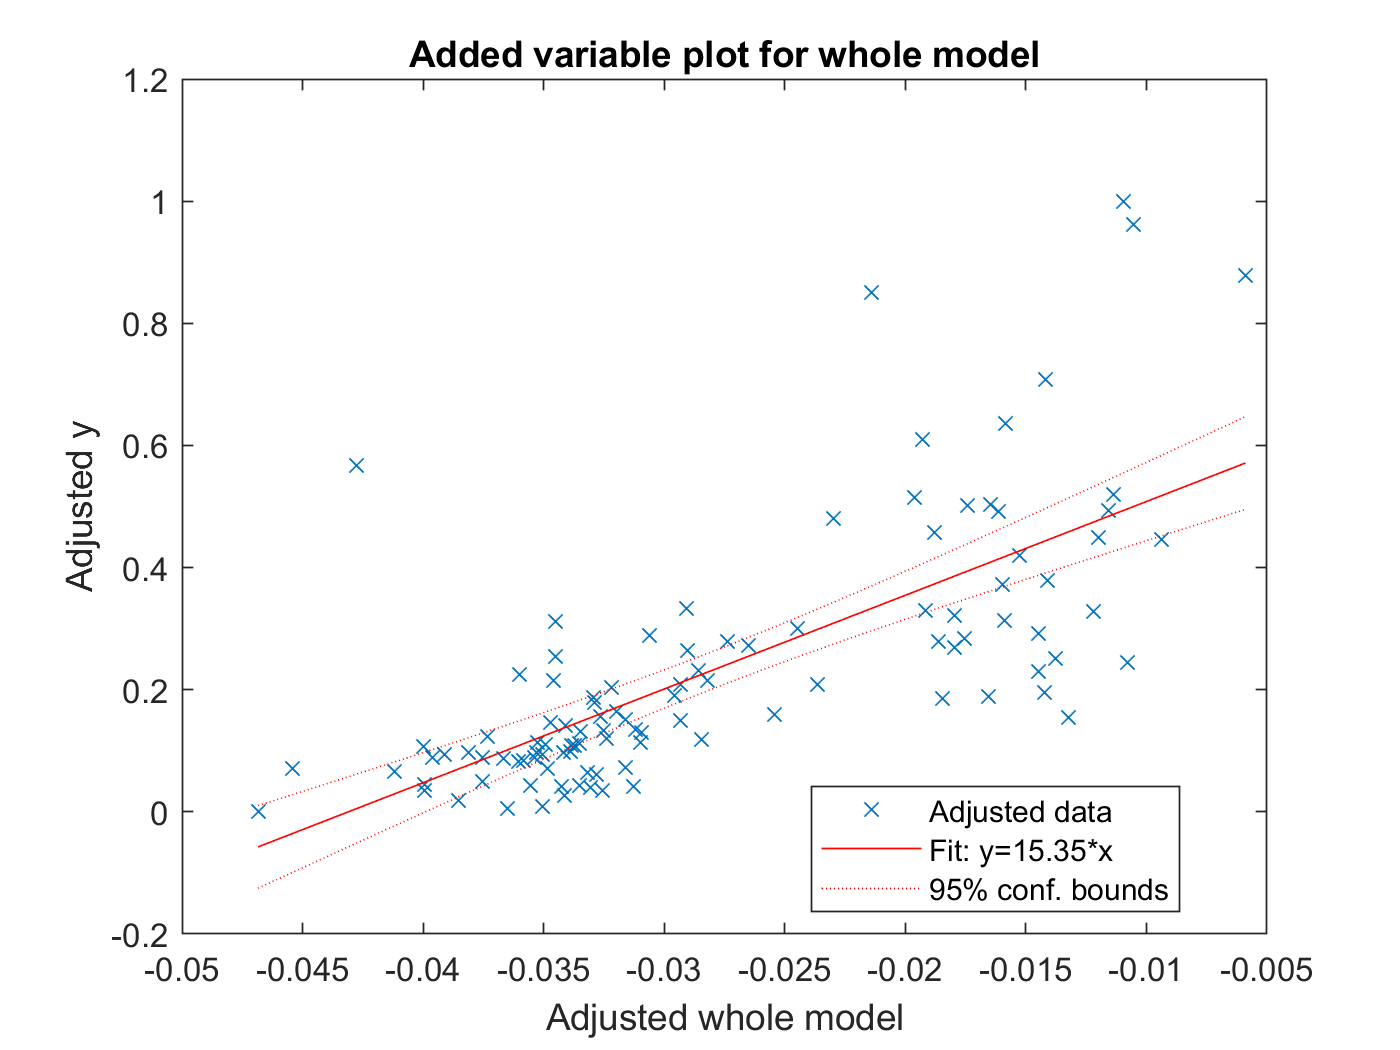



% figure
% hold on
% plot(y_trainValid_First_RUL,yhat_trainValid_IcFirst,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'
%capHat = Ic(1)
figure
plot(mdl_Linear_IcFirst_Rul)

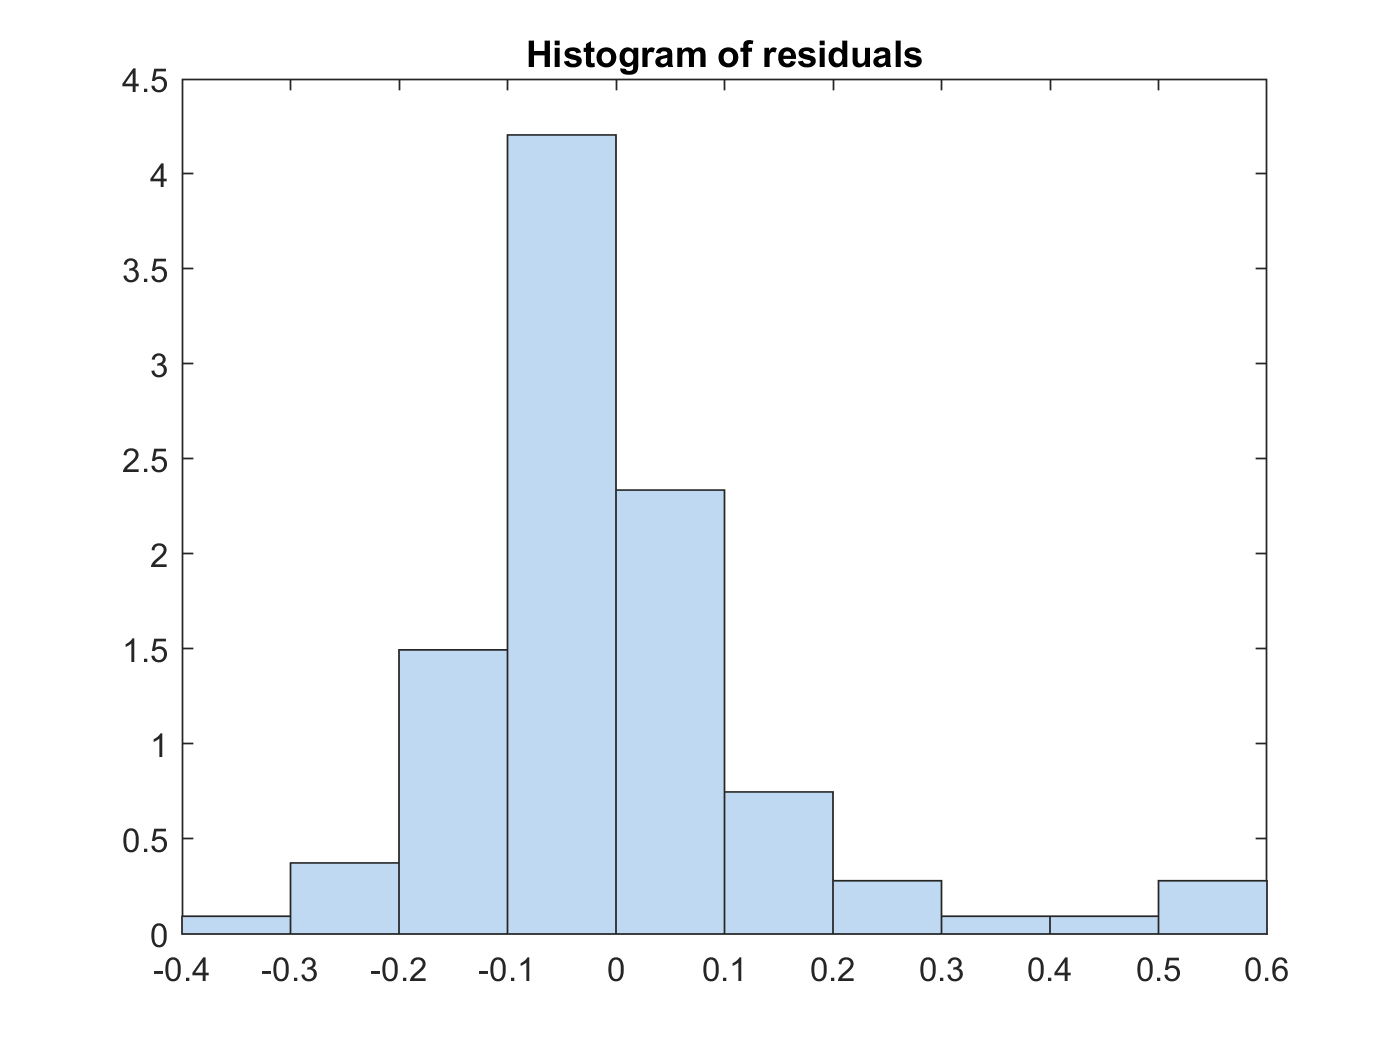

plotResiduals(mdl_Linear_IcFirst_Rul)

figure
yfit_trainValid_IcFirst = predict(mdl_Linear_IcFirst_Rul,x_trainValid_IcFirst_RUL);
yfit_trainValid_IcFirst'

ans =    -0.0574    0.1014    0.1239    0.0699    0.1620    0.0488    0.1540    0.1815    0.1356    0.1161    0.1471    0.0483    0.1579    0.1526    0.0297   -0.0355    0.1272    0.1768    0.1084    0.1116    0.0536    0.1188    0.0855    0.1235    0.0612    0.0765    0.1199    0.1368    0.0479    0.1440    0.1420    0.1259    0.1473    0.1858    0.1205    0.2251    0.0887    0.1865    0.1476    0.1624    0.1827    0.1381    0.1289    0.2117    0.4586    0.1608    0.2716    0.1707    0.1568    0.3785


yfit_test_IcFirst = predict(mdl_Linear_IcFirst_Rul,x_test_IcFirst_RUL);
yfit_test_IcFirst'

ans =     0.0906    0.1488    0.1480    0.0829    0.1129    0.1738    0.1901    0.4795    0.3772    0.4859    0.3250    0.5560



y_trainValid_First_RUL'

ans =          0    0.0056    0.0085    0.0188    0.0348    0.0348    0.0405    0.0414    0.0414    0.0424    0.0433    0.0452    0.0612    0.0650    0.0659    0.0706    0.0706    0.0725    0.0819    0.0847    0.0895    0.0895    0.0895    0.0932    0.0932    0.0970    0.0970    0.0979    0.1073    0.1083    0.1092    0.1102    0.1111    0.1130    0.1130    0.1186    0.1234    0.1299    0.1309    0.1337    0.1356    0.1422    0.1469    0.1488    0.1544    0.1563    0.1591    0.1648    0.1798    0.1855


y_test_First_RUL'

ans =     0.0292    0.0556    0.0885    0.1064    0.1224    0.1516    0.1949    0.2316    0.2872    0.3719    0.4981    0.8569


# denormaize


Yfit_trainValid_IcFirst = yfit_trainValid_IcFirst * yrate_First_RUL + ymin_First_RUL;
Yfit_test_IcFirst = yfit_test_IcFirst * yrate_First_RUL + ymin_First_RUL;
%Y_test_First_RUL = y_test_IcFirst_RUL * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
Yhat_trainValid_IcFirst = yhat_trainValid_IcFirst * yrate_First_RUL + ymin_First_RUL;

MAE_IcFirst = mean(abs(Yfit_trainValid_IcFirst-Y_trainValid_First_RUL))

MAE_IcFirst = 102.2707

adjMAE_IcFirst = MAE_IcFirst/range(Y_trainValid_First_RUL)

adjMAE_IcFirst = 0.0963

range(Y_trainValid_First_RUL) % Y_trainValid_First_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(Y_trainValid_First_RUL - Yhat_trainValid_IcFirst)'    % Errors

ans =    60.9573 -101.6468 -122.5493  -54.2849 -135.0875  -14.8745 -120.5917 -148.7702 -100.0286  -78.2677 -110.1726   -3.2585 -102.6744  -93.0797   38.5091  112.6804  -60.0594 -110.7140  -28.1546  -28.5666   38.0298  -31.1845    4.2502  -32.1687   33.9893   21.7533  -24.2854  -41.2595   63.1604  -37.9795  -34.7908  -16.6881  -38.4646  -77.3319   -7.9891 -113.0562   36.8179  -60.0308  -17.7467  -30.4586  -50.0515    4.3851   19.0983  -66.8259 -323.0497   -4.7700 -119.3905   -6.3078   24.4706 -204.9271


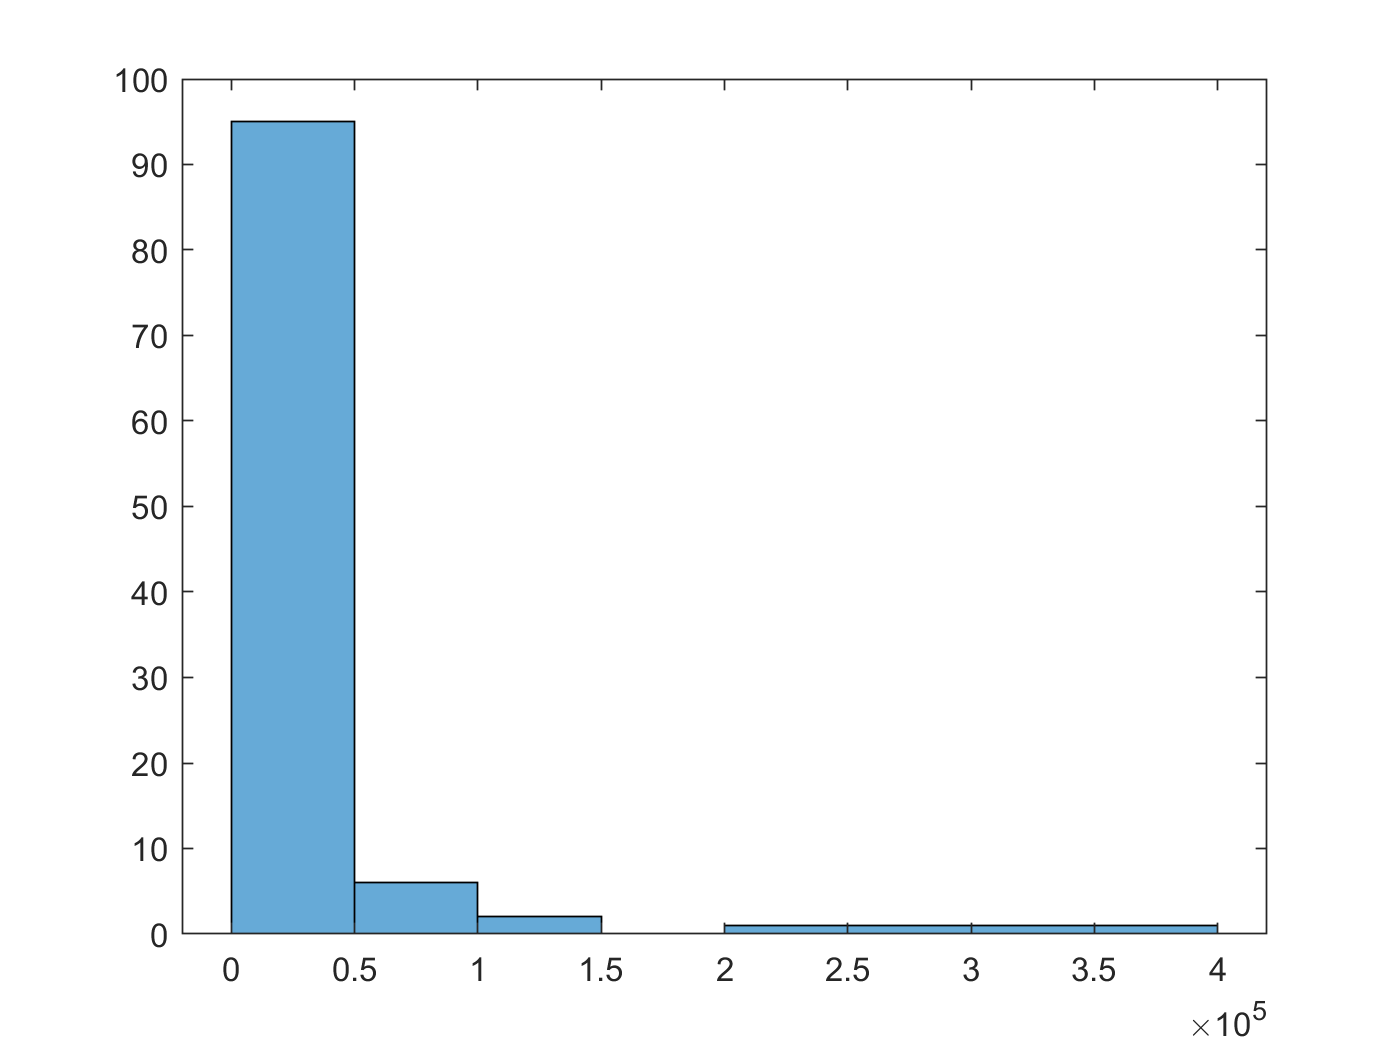

(Y_trainValid_First_RUL - Yhat_trainValid_IcFirst).^2;   % Squared Error
histogram((Y_trainValid_First_RUL - Yhat_trainValid_IcFirst).^2)

mean((Y_trainValid_First_RUL - Yhat_trainValid_IcFirst).^2);   % Mean Squared Error
RMSE_trainValid_IcFirst = sqrt(mean((Y_trainValid_First_RUL - Yhat_trainValid_IcFirst).^2))  % Root Mean Squared Error

RMSE_trainValid_IcFirst = 153.3772


RMSE_test_IcFirst = sqrt(mean((Y_test_First_RUL - Yfit_test_IcFirst).^2))

RMSE_test_IcFirst = 143.8644

Y_test_First_RUL - Yfit_test_IcFirst

ans =   -65.1750
  -99.0402
  -63.2277
   25.0023
   10.0665
  -23.5881
    5.1366
 -263.2319
  -95.6164
 -121.0405


Y_test_diff_IcFirst = horzcat(Y_test_First_RUL,(Y_test_First_RUL-Yfit_test_IcFirst))

Y_test_diff_IcFirst = 	1.0e+03 *

    0.1400   -0.0652
    0.1680   -0.0990
    0.2030   -0.0632
    0.2220    0.0250
    0.2390    0.0101
    0.2700   -0.0236
    0.3160    0.0051
    0.3550   -0.2632
    0.4140   -0.0956
    0.5040   -0.1210


Y_test_diff_percentage_IcFirst = abs(Y_test_First_RUL-Yfit_test_IcFirst)./Y_test_First_RUL.*100

Y_test_diff_percentage_IcFirst =    46.5536
   58.9525
   31.1466
   11.2623
    4.2119
    8.7363
    1.6255
   74.1498
   23.0957
   24.0160


Y_test_diff_percentage_avg_IcFirst = sum(Y_test_diff_percentage_IcFirst)/length(Y_test_diff_percentage_IcFirst)

Y_test_diff_percentage_avg_IcFirst = 28.6603

Y_trainValid_diff_IcFirst = horzcat(Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirst))

Y_trainValid_diff_IcFirst = 	1.0e+03 *

    0.1090    0.0610
    0.1150   -0.1016
    0.1180   -0.1225
    0.1290   -0.0543
    0.1460   -0.1351
    0.1460   -0.0149
    0.1520   -0.1206
    0.1530   -0.1488
    0.1530   -0.1000
    0.1540   -0.0783


Y_trainValid_diff_percentage_IcFirst = abs(Y_trainValid_First_RUL-Yfit_trainValid_IcFirst)./Y_trainValid_First_RUL.*100

Y_trainValid_diff_percentage_IcFirst =    55.9242
   88.3886
  103.8553
   42.0813
   92.5257
   10.1880
   79.3366
   97.2354
   65.3781
   50.8232


Y_trainValid_diff_percentage_avg_IcFirst = sum(Y_trainValid_diff_percentage_IcFirst)/length(Y_trainValid_diff_percentage_IcFirst)

Y_trainValid_diff_percentage_avg_IcFirst = 30.2418

num = 1:length(Y_trainValid_First_RUL);


result = horzcat(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirst),Y_trainValid_diff_percentage_IcFirst);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 	1.0e+03 *

    0.0010    0.1090    0.0610    0.0559
    0.0020    0.1150   -0.1016    0.0884
    0.0030    0.1180   -0.1225    0.1039
    0.0040    0.1290   -0.0543    0.0421
    0.0050    0.1460   -0.1351    0.0925
    0.0060    0.1460   -0.0149    0.0102
    0.0070    0.1520   -0.1206    0.0793
    0.0080    0.1530   -0.1488    0.0972
    0.0090    0.1530   -0.1000    0.0654
    0.0100    0.1540   -0.0783    0.0508


result_IcFirst = table(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_IcFirst),Y_trainValid_diff_percentage_IcFirst);
result_IcFirst.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_IcFirst

result_IcFirst = 107×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       109     60.957    55.924 
       2       115    -101.65    88.389 
       3       118    -122.55    103.86 
       4       129    -54.285    42.081 
       5       146    -135.09    92.526 
       6       146    -14.874    10.188 
       7       152    -120.59    79.337 
       8       153    -148.77    97.235 
       9       153    -100.03    65.378 
      10       154    -78.268    50.823 
      11       155    -110.17    71.079 
      12       157    -3.2585    2.0755 
      13       174    -102.67    59.008 
      14       178     -93.08    52.292 
      15       179     38.509    21.513 
      16       184     112.68    61.239 


result_IcFirst_summary = table(RMSE_test_IcFirst,Y_trainValid_diff_percentage_avg_IcFirst);
result_IcFirst_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_IcFirst_summary 

result_IcFirst_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    143.86      30.242  


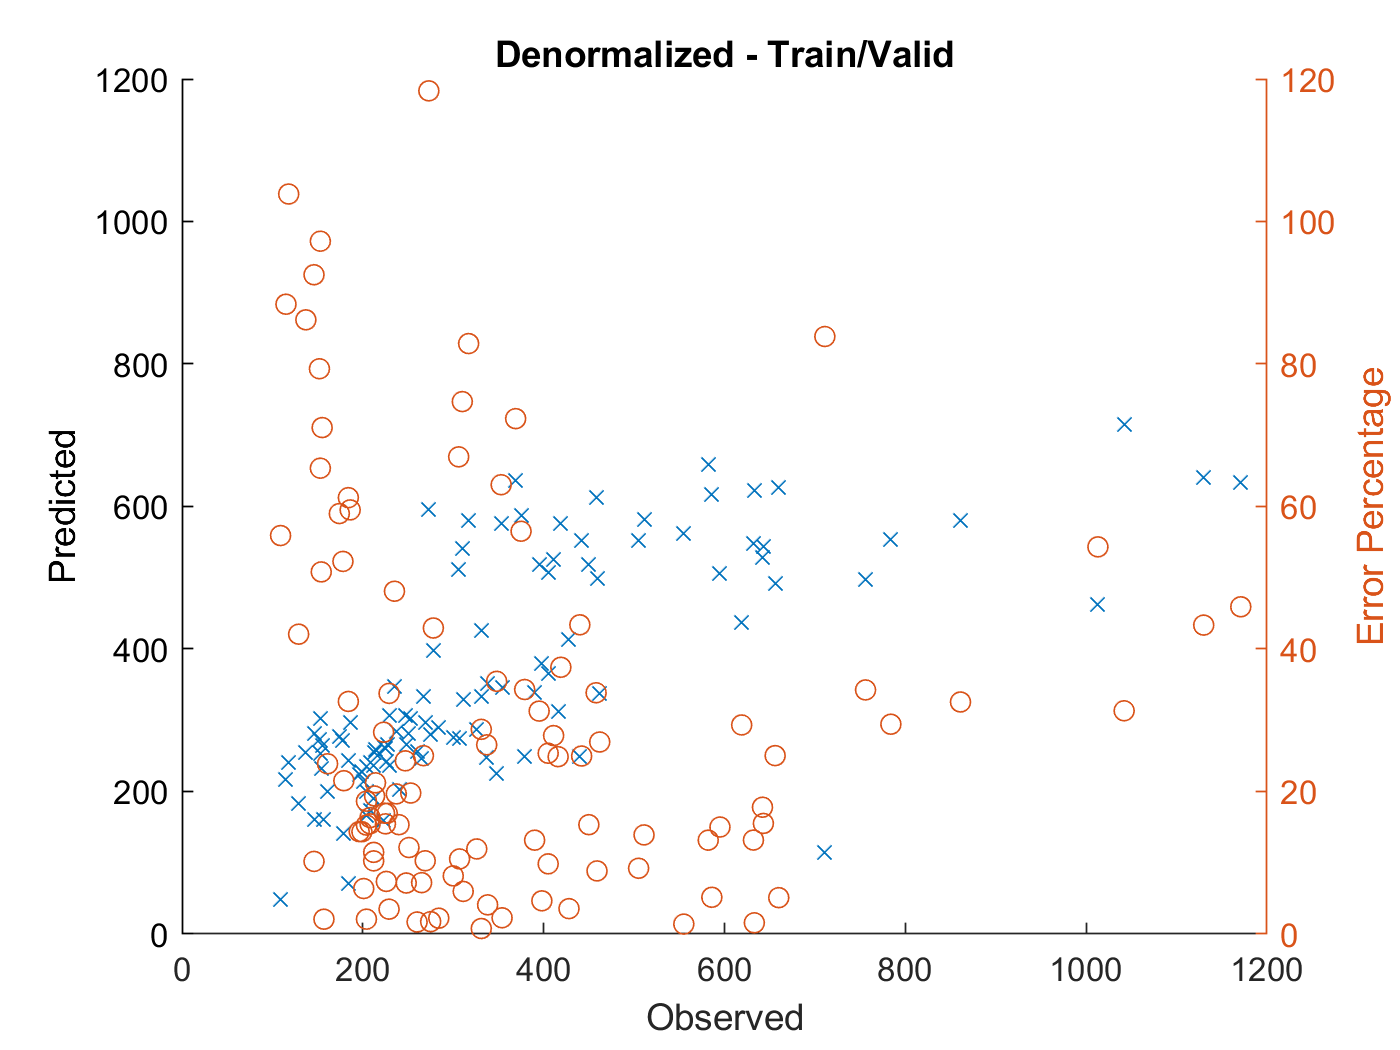


figure
hold on
plot(Y_trainValid_First_RUL,Yfit_trainValid_IcFirst,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_First_RUL,Y_trainValid_diff_percentage_IcFirst,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcFirst

RMSE_test_IcFirst = 143.8644

Y_trainValid_diff_percentage_avg_IcFirst

Y_trainValid_diff_percentage_avg_IcFirst = 30.2418

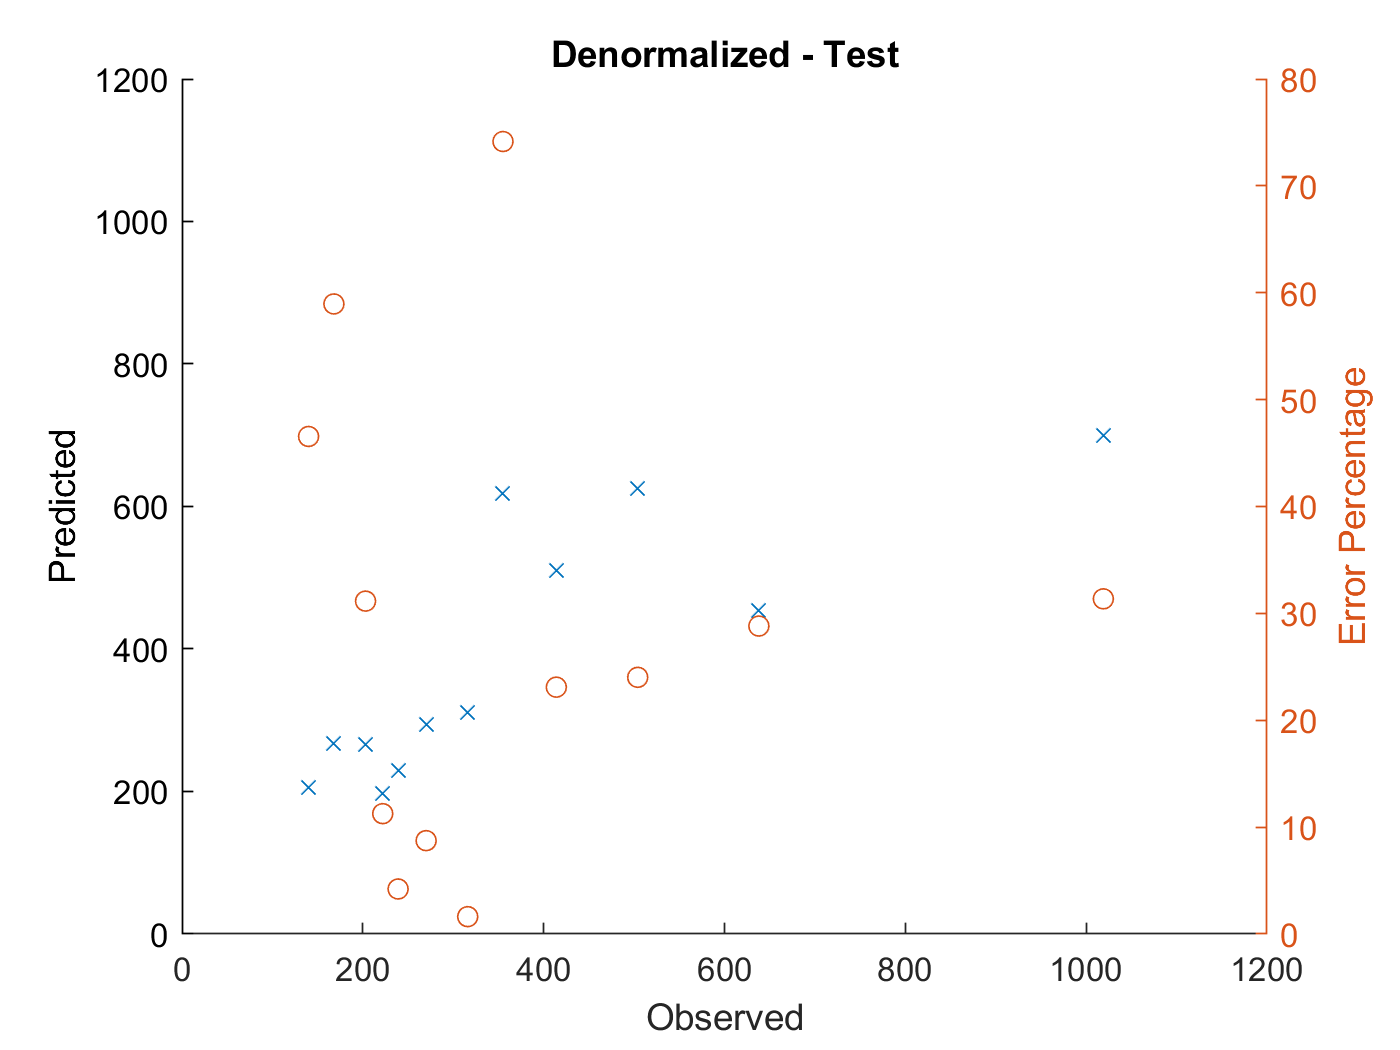


figure
hold on
plot(Y_test_First_RUL,Yfit_test_IcFirst,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_First_RUL,Y_test_diff_percentage_IcFirst,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - VdFirstFull (100)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff_VdFirstFull = mdl_Linear_VdFirstFull_Rul.Coefficients.Estimate;
coeff_VdFirstFull'

ans = 	1.0e+03 *

    0.0240    0.0361    0.0891   -0.1034   -0.3995    0.3122   -0.1056    0.3672    0.2037    0.5492   -0.8728   -1.7581    1.2289    0.4359   -0.4333    0.2501    0.7673    0.3373   -0.4388   -0.4414   -0.3576   -0.0504    0.6865   -0.1982   -0.5142    0.1295    0.8806    0.1646   -0.6459   -0.4514    0.1772   -0.9528    0.4617    0.5136    0.2622    0.4605   -0.5819    0.2692    0.4984   -0.2580   -0.2534   -1.3572   -0.1065    0.3744    0.6430   -0.6064    1.0888    0.5692    0.3503   -0.5497


x_trainValid_VdFirstFull_RUL(1,:)

ans =     0.9848    0.9374    0.9141    0.9011    0.8929    0.8873    0.8829    0.8793    0.8762    0.8737    0.8711    0.8688    0.8665    0.8646    0.8626    0.8605    0.8585    0.8566    0.8547    0.8527    0.8508    0.8488    0.8469    0.8448    0.8429    0.8409    0.8389    0.8367    0.8348    0.8327    0.8307    0.8284    0.8263    0.8241    0.8220    0.8197    0.8175    0.8150    0.8127    0.8101    0.8076    0.8051    0.8025    0.7998    0.7970    0.7943    0.7914    0.7887    0.7856    0.7827


yhat_trainValid_VdFirstFull = x_trainValid_VdFirstFull_RUL*coeff_VdFirstFull(2:101)+coeff_VdFirstFull(1);
yhat_trainValid_VdFirstFull'

ans =    -0.0086   -0.0006    0.0036   -0.0127    0.0478    0.0326    0.0337    0.0670    0.0626    0.0407   -0.0024    0.0609    0.0902    0.1019    0.0819    0.0747    0.0943    0.0955    0.0460    0.0623    0.0601    0.1078    0.0967    0.0403    0.1045    0.1497    0.0450    0.0837    0.0658    0.1052    0.1504    0.0916    0.1095    0.1614    0.1278    0.1573    0.1639    0.1208    0.1446    0.1546    0.1259    0.1237    0.1247    0.1462    0.1850    0.1996    0.1569    0.1657    0.1551    0.0674


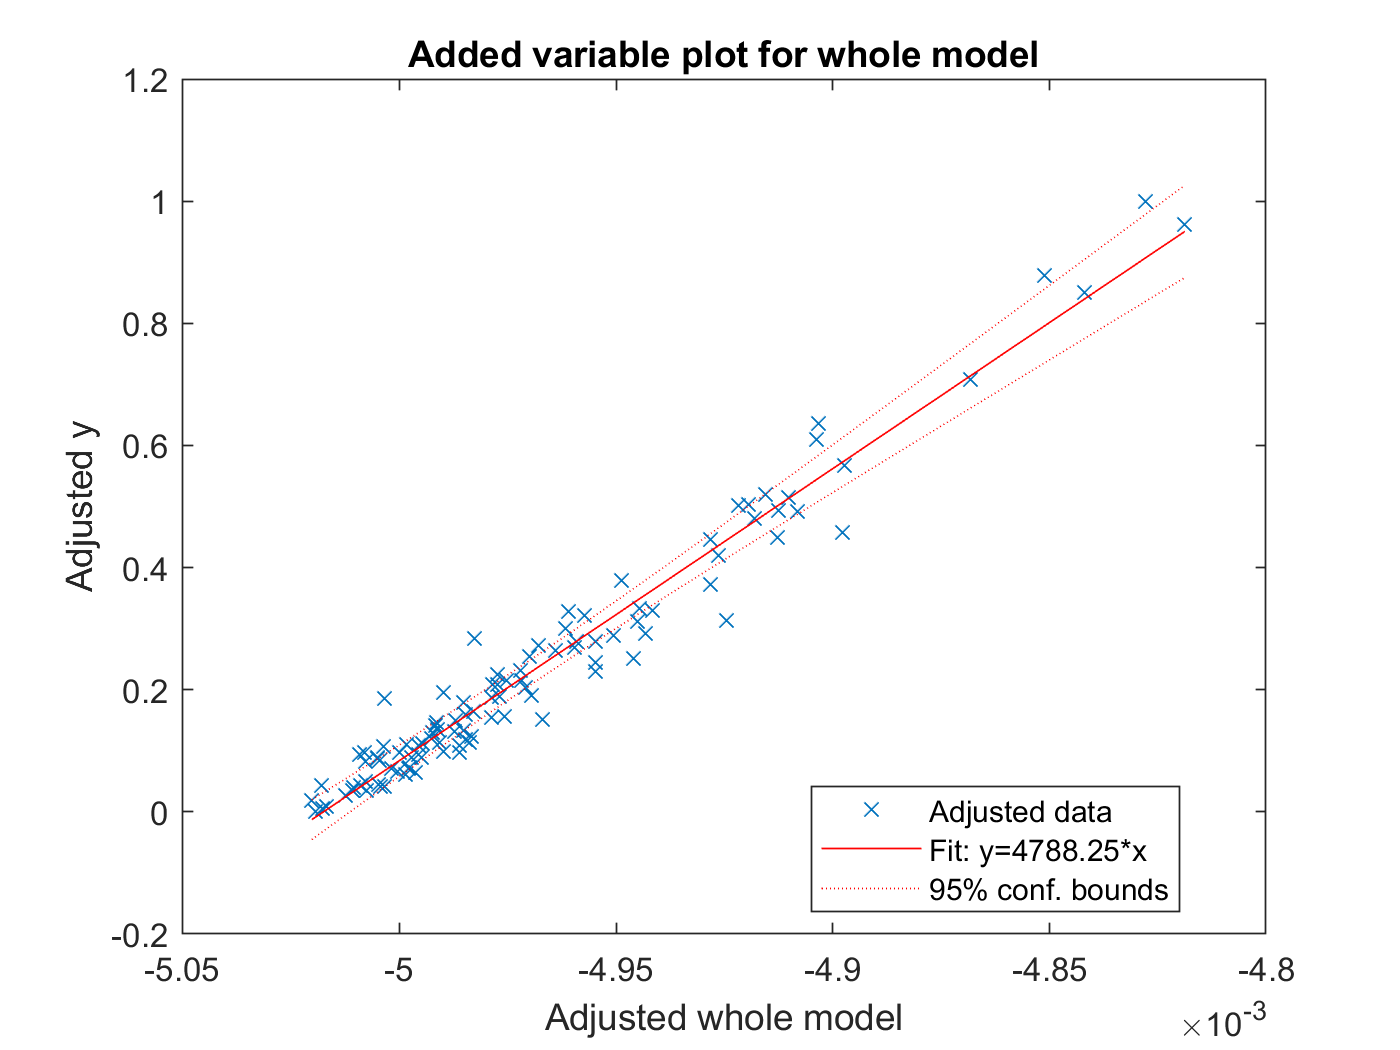



% figure
% hold on
% plot(y_trainValid_First_RUL,yhat_trainValid_VdFirstFull,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'
%capHat = Ic(1)
figure
plot(mdl_Linear_VdFirstFull_Rul)

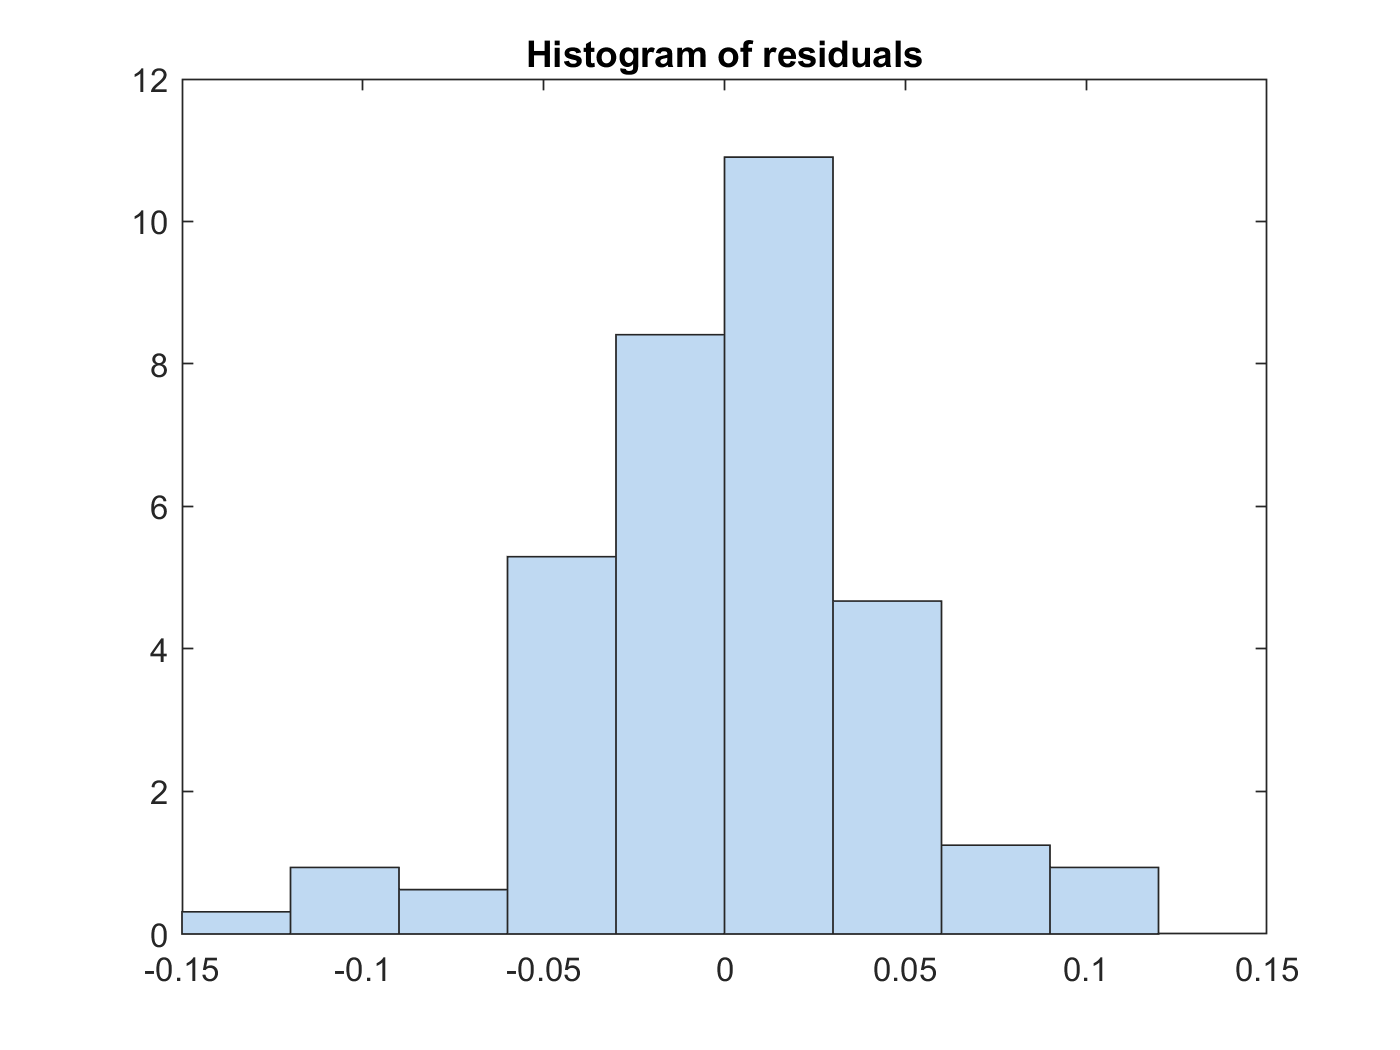

plotResiduals(mdl_Linear_VdFirstFull_Rul)

figure
yfit_trainValid_VdFirstFull = predict(mdl_Linear_VdFirstFull_Rul,x_trainValid_VdFirstFull_RUL);
yfit_trainValid_VdFirstFull'

ans =    -0.0086   -0.0006    0.0036   -0.0127    0.0478    0.0326    0.0337    0.0670    0.0626    0.0407   -0.0024    0.0609    0.0902    0.1019    0.0819    0.0747    0.0943    0.0955    0.0460    0.0623    0.0601    0.1078    0.0967    0.0403    0.1045    0.1497    0.0450    0.0837    0.0658    0.1052    0.1504    0.0916    0.1095    0.1614    0.1278    0.1573    0.1639    0.1208    0.1446    0.1546    0.1259    0.1237    0.1247    0.1462    0.1850    0.1996    0.1569    0.1657    0.1551    0.0674


yfit_test_VdFirstFull = predict(mdl_Linear_VdFirstFull_Rul,x_test_VdFirstFull_RUL);
yfit_test_VdFirstFull'

ans =     2.2582    0.4265   -0.1008    0.0160    0.2337    0.5105    0.0345    0.2340    0.3545    0.5026    0.3545    0.4237



y_trainValid_First_RUL'

ans =          0    0.0056    0.0085    0.0188    0.0348    0.0348    0.0405    0.0414    0.0414    0.0424    0.0433    0.0452    0.0612    0.0650    0.0659    0.0706    0.0706    0.0725    0.0819    0.0847    0.0895    0.0895    0.0895    0.0932    0.0932    0.0970    0.0970    0.0979    0.1073    0.1083    0.1092    0.1102    0.1111    0.1130    0.1130    0.1186    0.1234    0.1299    0.1309    0.1337    0.1356    0.1422    0.1469    0.1488    0.1544    0.1563    0.1591    0.1648    0.1798    0.1855


y_test_First_RUL'

ans =     0.0292    0.0556    0.0885    0.1064    0.1224    0.1516    0.1949    0.2316    0.2872    0.3719    0.4981    0.8569


# denormaize


Yfit_trainValid_VdFirstFull = yfit_trainValid_VdFirstFull * yrate_First_RUL + ymin_First_RUL;
Yfit_test_VdFirstFull = yfit_test_VdFirstFull * yrate_First_RUL + ymin_First_RUL;
%Y_test_First_RUL = y_test_VdFirst_RUL * yrate_VdFirst_RUL + ymin_VdFirst_RUL;
Yhat_trainValid_VdFirstFull = yhat_trainValid_VdFirstFull * yrate_First_RUL + ymin_First_RUL;

MAE_VdFirstFull = mean(abs(Yfit_trainValid_VdFirstFull-Y_trainValid_First_RUL))

MAE_VdFirstFull = 32.3664

adjMAE_VdFirstFull = MAE_VdFirstFull/range(Y_trainValid_First_RUL)

adjMAE_VdFirstFull = 0.0305

range(Y_trainValid_First_RUL) % Y_trainValid_First_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(Y_trainValid_First_RUL - Yhat_trainValid_VdFirstFull)'    % Errors

ans =     9.1625    6.6745    5.1407   33.5325  -13.7111    2.3433    7.1898  -27.1844  -22.5113    1.7369   48.5233  -16.6641  -30.7995  -39.1650  -16.9889   -4.3419  -25.1969  -24.4296   38.1881   23.8485   31.1624  -19.4695   -7.6814   56.2099  -11.9855  -56.0050   55.2042   15.1244   44.0810    3.2489  -43.7308   19.7157    1.7576  -51.4443  -15.7080  -41.0719  -43.0613    9.6629  -14.5145  -22.1389   10.2697   19.6546   23.5583    2.7037  -32.4547  -45.9273    2.3418   -0.9543   26.3032  125.3844


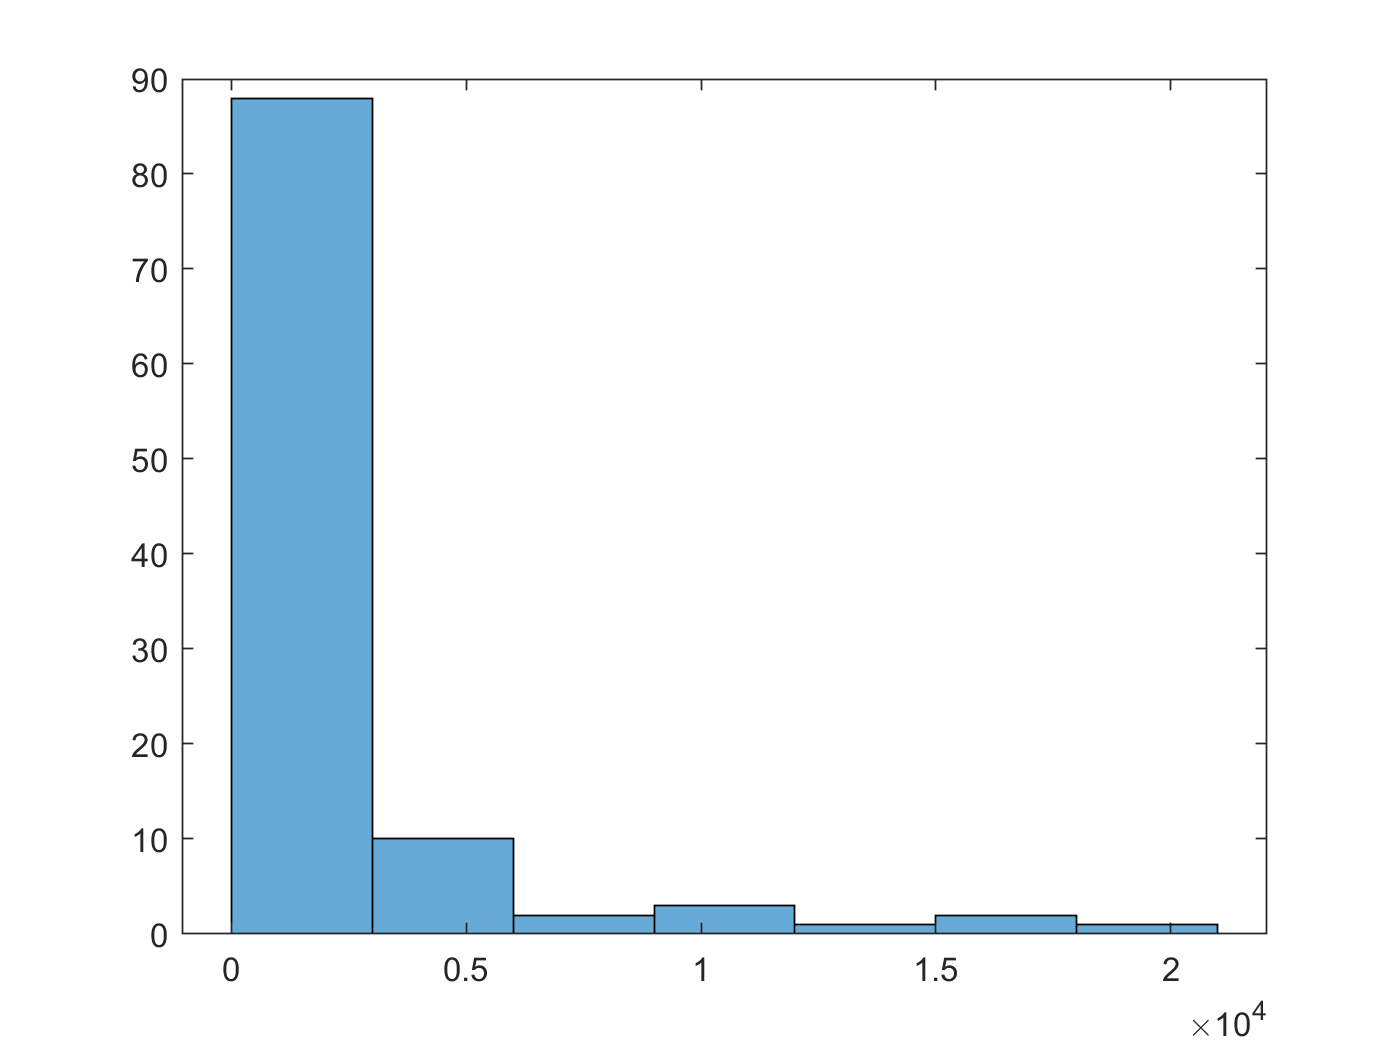

(Y_trainValid_First_RUL - Yhat_trainValid_VdFirstFull).^2;   % Squared Error
histogram((Y_trainValid_First_RUL - Yhat_trainValid_VdFirstFull).^2)

mean((Y_trainValid_First_RUL - Yhat_trainValid_VdFirstFull).^2);   % Mean Squared Error
RMSE_trainValid_VdFirstFull = sqrt(mean((Y_trainValid_First_RUL - Yhat_trainValid_VdFirstFull).^2))  % Root Mean Squared Error

RMSE_trainValid_VdFirstFull = 44.1582


RMSE_test_VdFirstFull = sqrt(mean((Y_test_First_RUL - Yfit_test_VdFirstFull).^2))

RMSE_test_VdFirstFull = 722.0455

Y_test_First_RUL - Yfit_test_VdFirstFull

ans = 	1.0e+03 *

   -2.3672
   -0.3939
    0.2011
    0.0960
   -0.1182
   -0.3812
    0.1704
   -0.0025
   -0.0715
   -0.1387


Y_test_diff_VdFirstFull = horzcat(Y_test_First_RUL,(Y_test_First_RUL-Yfit_test_VdFirstFull))

Y_test_diff_VdFirstFull = 	1.0e+03 *

    0.1400   -2.3672
    0.1680   -0.3939
    0.2030    0.2011
    0.2220    0.0960
    0.2390   -0.1182
    0.2700   -0.3812
    0.3160    0.1704
    0.3550   -0.0025
    0.4140   -0.0715
    0.5040   -0.1387


Y_test_diff_percentage_VdFirstFull = abs(Y_test_First_RUL-Yfit_test_VdFirstFull)./Y_test_First_RUL.*100

Y_test_diff_percentage_VdFirstFull = 	1.0e+03 *

    1.6909
    0.2345
    0.0991
    0.0432
    0.0494
    0.1412
    0.0539
    0.0007
    0.0173
    0.0275


Y_test_diff_percentage_avg_VdFirstFull = sum(Y_test_diff_percentage_VdFirstFull)/length(Y_test_diff_percentage_VdFirstFull)

Y_test_diff_percentage_avg_VdFirstFull = 202.2312

Y_trainValid_diff_VdFirstFull = horzcat(Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirstFull))

Y_trainValid_diff_VdFirstFull = 	1.0e+03 *

    0.1090    0.0092
    0.1150    0.0067
    0.1180    0.0051
    0.1290    0.0335
    0.1460   -0.0137
    0.1460    0.0023
    0.1520    0.0072
    0.1530   -0.0272
    0.1530   -0.0225
    0.1540    0.0017


Y_trainValid_diff_percentage_VdFirstFull = abs(Y_trainValid_First_RUL-Yfit_trainValid_VdFirstFull)./Y_trainValid_First_RUL.*100

Y_trainValid_diff_percentage_VdFirstFull =     8.4059
    5.8039
    4.3565
   25.9942
    9.3912
    1.6050
    4.7301
   17.7676
   14.7133
    1.1279


Y_trainValid_diff_percentage_avg_VdFirstFull = sum(Y_trainValid_diff_percentage_VdFirstFull)/length(Y_trainValid_diff_percentage_VdFirstFull)

Y_trainValid_diff_percentage_avg_VdFirstFull = 10.2642

num = 1:length(Y_trainValid_First_RUL);


result = horzcat(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirstFull),Y_trainValid_diff_percentage_VdFirstFull);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 	1.0e+03 *

    0.0010    0.1090    0.0092    0.0084
    0.0020    0.1150    0.0067    0.0058
    0.0030    0.1180    0.0051    0.0044
    0.0040    0.1290    0.0335    0.0260
    0.0050    0.1460   -0.0137    0.0094
    0.0060    0.1460    0.0023    0.0016
    0.0070    0.1520    0.0072    0.0047
    0.0080    0.1530   -0.0272    0.0178
    0.0090    0.1530   -0.0225    0.0147
    0.0100    0.1540    0.0017    0.0011


result_VdFirstFull = table(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirstFull),Y_trainValid_diff_percentage_VdFirstFull);
result_VdFirstFull.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_VdFirstFull

result_VdFirstFull = 107×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       109     9.1625    8.4059 
       2       115     6.6745    5.8039 
       3       118     5.1407    4.3565 
       4       129     33.533    25.994 
       5       146    -13.711    9.3912 
       6       146     2.3433     1.605 
       7       152     7.1898    4.7301 
       8       153    -27.184    17.768 
       9       153    -22.511    14.713 
      10       154     1.7369    1.1279 
      11       155     48.523    31.305 
      12       157    -16.664    10.614 
      13       174      -30.8    17.701 
      14       178    -39.165    22.003 
      15       179    -16.989     9.491 
      16       184    -4.3419    2.3597 


result_VdFirstFull_summary = table(RMSE_test_VdFirstFull,Y_trainValid_diff_percentage_avg_VdFirstFull);
result_VdFirstFull_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_VdFirstFull_summary 

result_VdFirstFull_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    722.05      10.264  


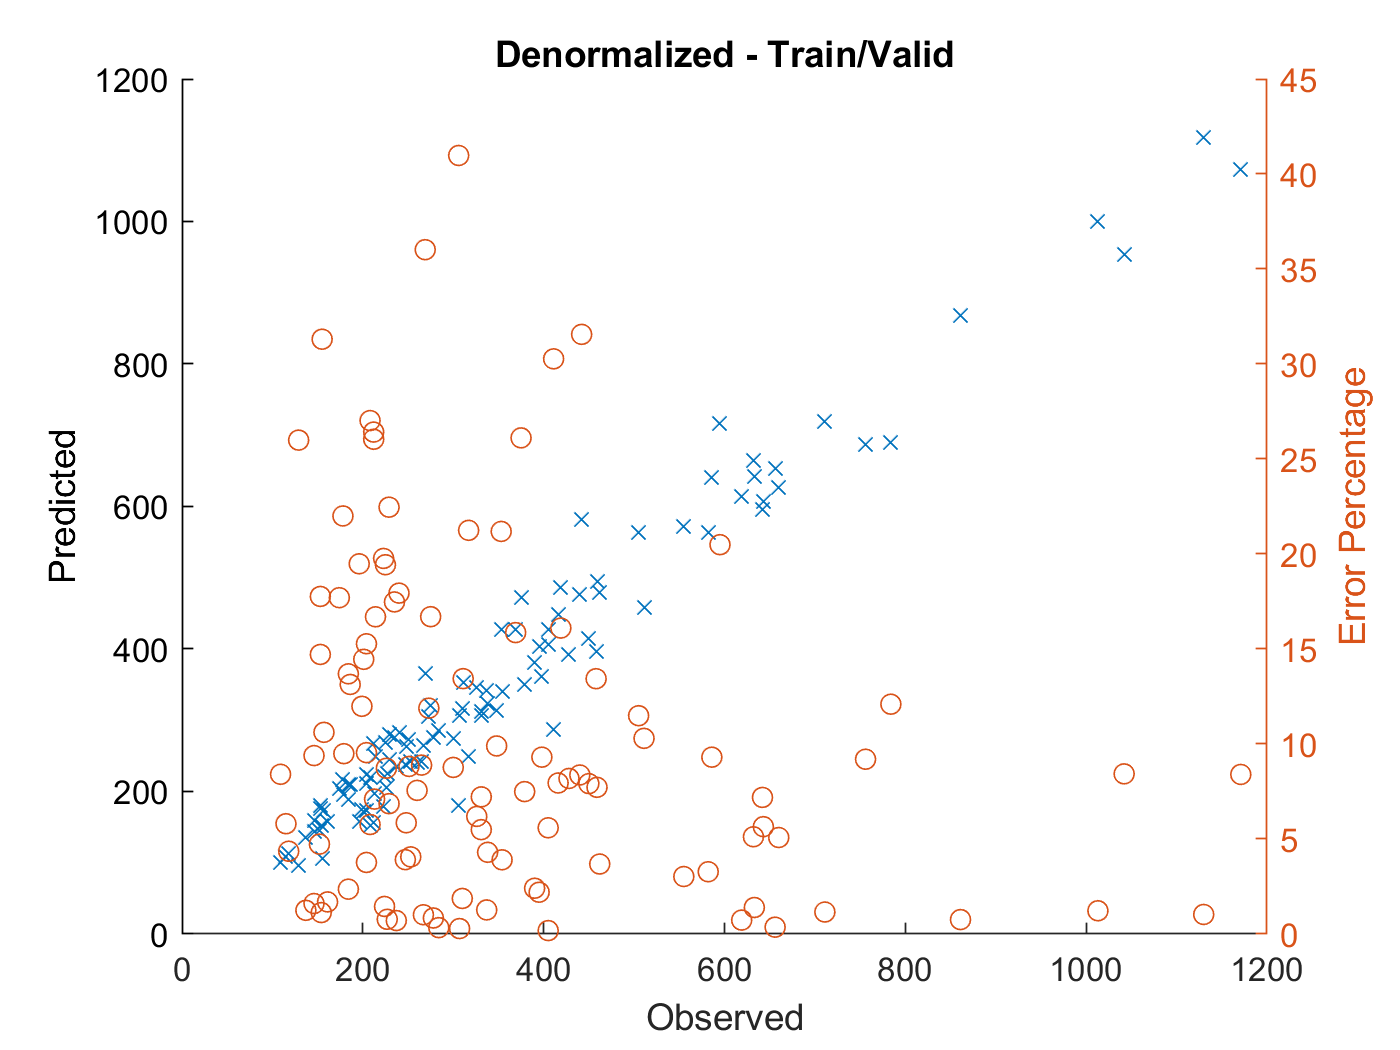


figure
hold on
plot(Y_trainValid_First_RUL,Yfit_trainValid_VdFirstFull,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_First_RUL,Y_trainValid_diff_percentage_VdFirstFull,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdFirstFull

RMSE_test_VdFirstFull = 722.0455

Y_trainValid_diff_percentage_avg_VdFirstFull

Y_trainValid_diff_percentage_avg_VdFirstFull = 10.2642

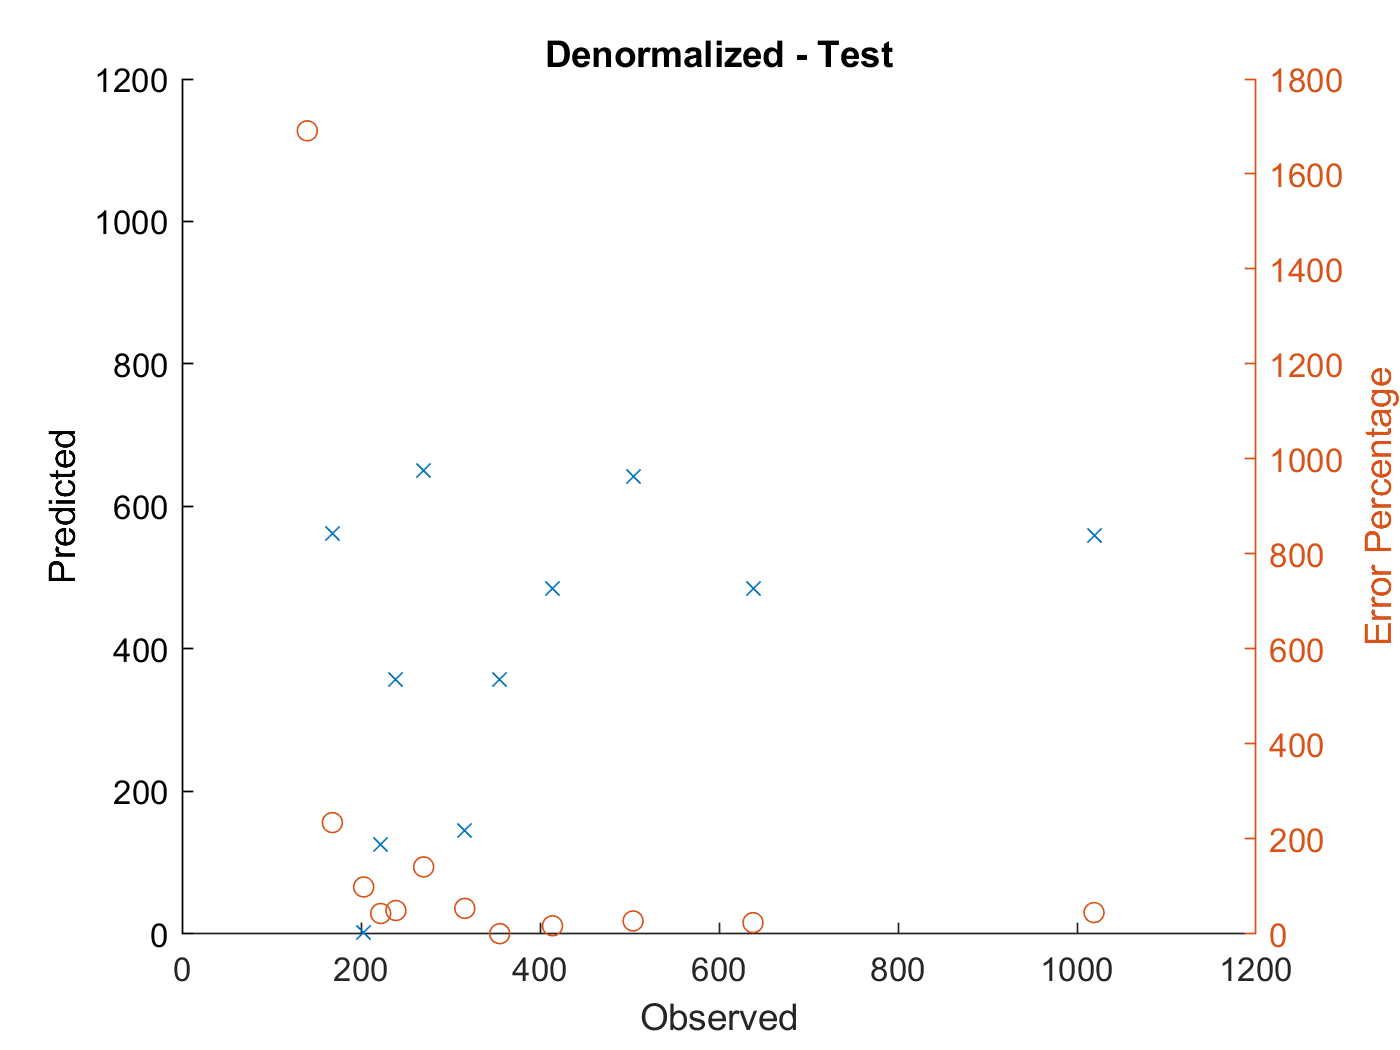


figure
hold on
plot(Y_test_First_RUL,Yfit_test_VdFirstFull,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_First_RUL,Y_test_diff_percentage_VdFirstFull,'o');

hold off
title 'Denormalized - Test'

# 선형회귀 - 예측 - VdFirst (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff_VdFirst = mdl_Linear_VdFirst_Rul.Coefficients.Estimate;
coeff_VdFirst'

ans =    -1.2423   -6.8065 -116.8047   36.7605  169.6272  204.6103 -628.4832  161.7344  126.8218  305.2670 -230.9787  -70.1645   97.4400  -95.6305   66.2937  -15.6438    0.3523    0.4298    5.5222   32.5034         0


x_trainValid_VdFirst_RUL(1,:)

ans =     0.9260    0.8799    0.8667    0.8566    0.8469    0.8368    0.8263    0.8150    0.8024    0.7885    0.7731    0.7557    0.7357    0.7121    0.6815    0.6271    0.4616    0.0069    0.0008    0.0008


yhat_trainValid_VdFirst = x_trainValid_VdFirst_RUL*coeff_VdFirst(2:21)+coeff_VdFirst(1);
yhat_trainValid_VdFirst'

ans =     0.0808    0.0418    0.0034   -0.0485    0.0896    0.0604   -0.0774    0.0549    0.0460    0.0788   -0.0696   -0.0967    0.1002    0.1450    0.0073   -0.0424    0.1227    0.0562    0.1551    0.1340    0.0025    0.1269    0.0813    0.1208    0.0437    0.2211    0.0979    0.0145    0.0711    0.0586    0.1718    0.0385    0.1171    0.1525    0.0897    0.1934    0.1866    0.1621    0.1009    0.1998    0.1890    0.1069    0.1543    0.1749    0.2801    0.1570    0.3049    0.2144    0.1551    0.2247


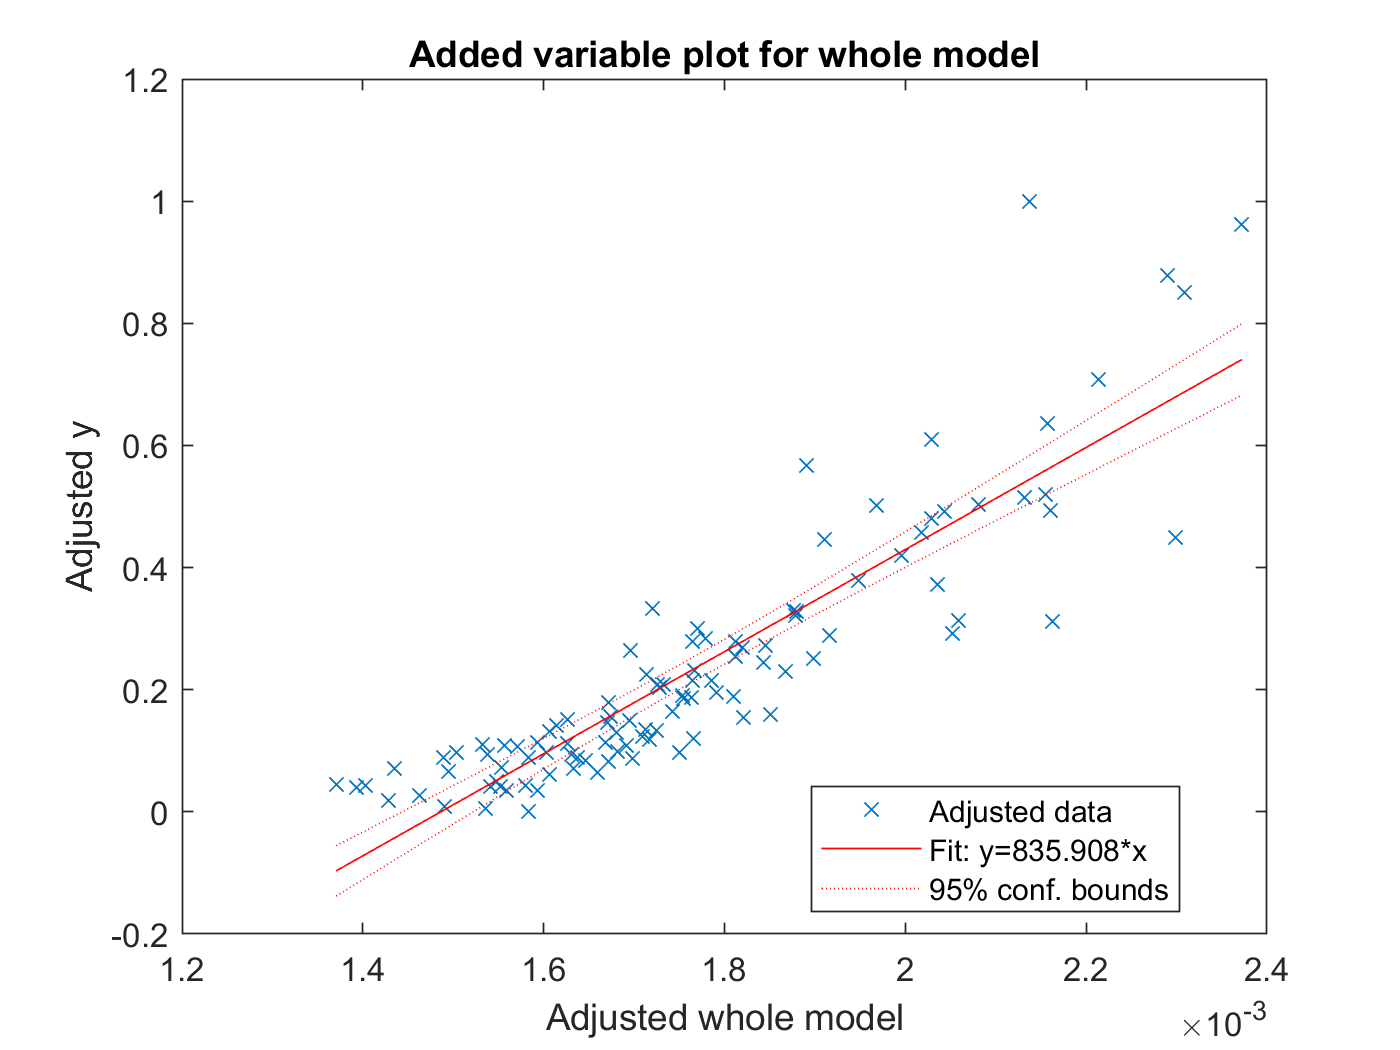



% figure
% hold on
% plot(y_trainValid_First_RUL,yhat_trainValid_VdFirst,'x')
% xlabel("Observed")
% ylabel("Predicted")
% hold off
% title 'Normalized'
%capHat = Ic(1)
figure
plot(mdl_Linear_VdFirst_Rul)

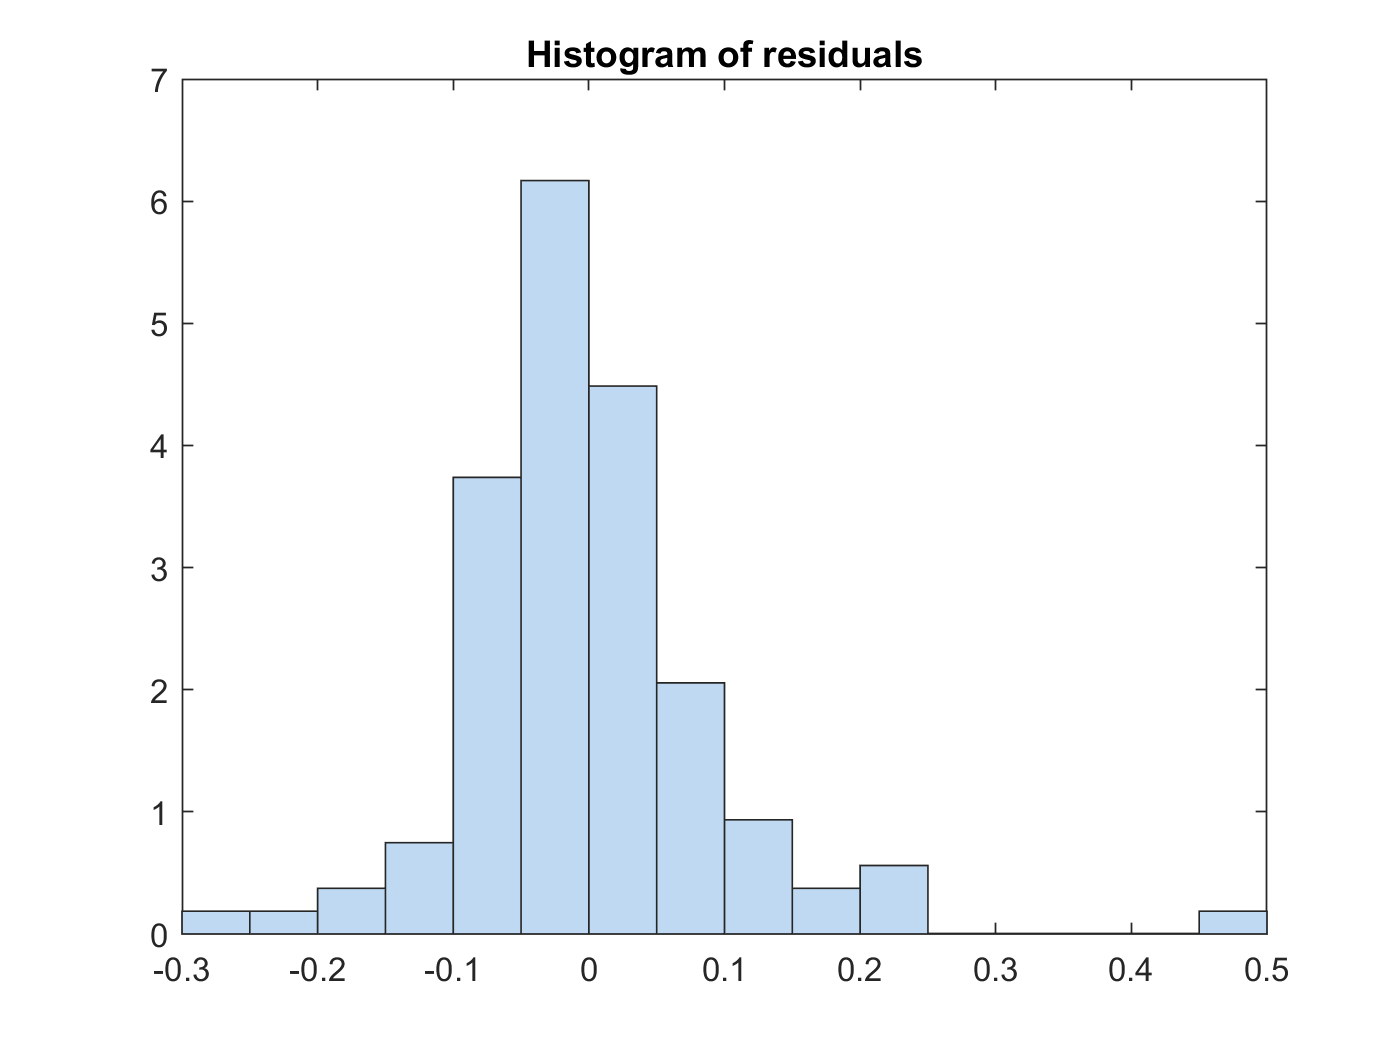

plotResiduals(mdl_Linear_VdFirst_Rul)

figure
yfit_trainValid_VdFirst = predict(mdl_Linear_VdFirst_Rul,x_trainValid_VdFirst_RUL);
yfit_trainValid_VdFirst'

ans =     0.0808    0.0418    0.0034   -0.0485    0.0896    0.0604   -0.0774    0.0549    0.0460    0.0788   -0.0696   -0.0967    0.1002    0.1450    0.0073   -0.0424    0.1227    0.0562    0.1551    0.1340    0.0025    0.1269    0.0813    0.1208    0.0437    0.2211    0.0979    0.0145    0.0711    0.0586    0.1718    0.0385    0.1171    0.1525    0.0897    0.1934    0.1866    0.1621    0.1009    0.1998    0.1890    0.1069    0.1543    0.1749    0.2801    0.1570    0.3049    0.2144    0.1551    0.2247


yfit_test_VdFirst = predict(mdl_Linear_VdFirst_Rul,x_test_VdFirst_RUL);
yfit_test_VdFirst'

ans =    -0.0495    0.0081    0.1025    0.1144    0.0618    0.1307    0.2049    0.3159    0.2882    0.8268    0.4849    0.5402



y_trainValid_First_RUL'

ans =          0    0.0056    0.0085    0.0188    0.0348    0.0348    0.0405    0.0414    0.0414    0.0424    0.0433    0.0452    0.0612    0.0650    0.0659    0.0706    0.0706    0.0725    0.0819    0.0847    0.0895    0.0895    0.0895    0.0932    0.0932    0.0970    0.0970    0.0979    0.1073    0.1083    0.1092    0.1102    0.1111    0.1130    0.1130    0.1186    0.1234    0.1299    0.1309    0.1337    0.1356    0.1422    0.1469    0.1488    0.1544    0.1563    0.1591    0.1648    0.1798    0.1855


y_test_First_RUL'

ans =     0.0292    0.0556    0.0885    0.1064    0.1224    0.1516    0.1949    0.2316    0.2872    0.3719    0.4981    0.8569


# denormaize


Yfit_trainValid_VdFirst = yfit_trainValid_VdFirst * yrate_First_RUL + ymin_First_RUL;
Yfit_test_VdFirst = yfit_test_VdFirst * yrate_First_RUL + ymin_First_RUL;
%Y_test_First_RUL = y_test_VdFirst_RUL * yrate_VdFirst_RUL + ymin_VdFirst_RUL;
Yhat_trainValid_VdFirst = yhat_trainValid_VdFirst * yrate_First_RUL + ymin_First_RUL;

MAE_VdFirst = mean(abs(Yfit_trainValid_VdFirst-Y_trainValid_First_RUL))

MAE_VdFirst = 69.6480

adjMAE_VdFirst = MAE_VdFirst/range(Y_trainValid_First_RUL)

adjMAE_VdFirst = 0.0656

range(Y_trainValid_First_RUL) % Y_trainValid_First_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(Y_trainValid_First_RUL - Yhat_trainValid_VdFirst)'    % Errors

ans =   -85.8314  -38.4325    5.4336   71.5211  -58.2059  -27.1128  125.2484  -14.3428   -4.8613  -38.7234  119.8674  150.6436  -41.3642  -84.9418   62.2954  120.0230  -55.2886   17.3205  -77.7669  -52.3599   92.3409  -39.7961    8.6665  -29.3136   52.6124 -131.7791   -0.9911   88.6102   38.4512   52.7571  -66.5046   76.0776   -6.3402  -41.9684   24.7644  -79.4213  -67.1766  -34.1294   31.8057  -70.1434  -56.7205   37.4207   -7.8433  -27.7507 -133.4721   -0.6893 -154.7698  -52.6523   26.3226  -41.5887


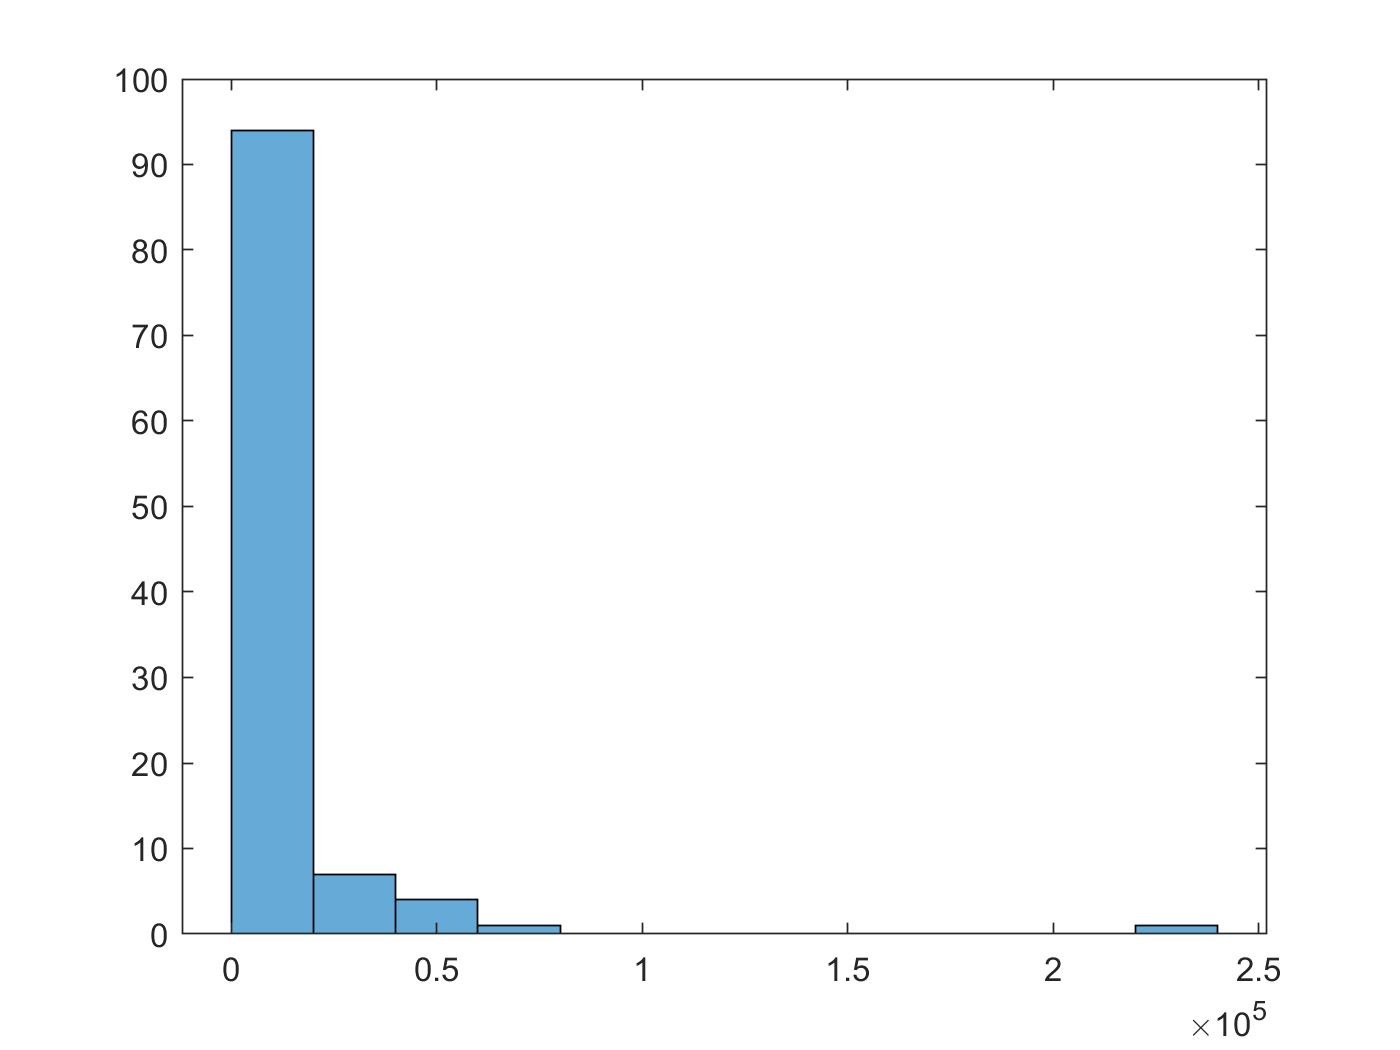

(Y_trainValid_First_RUL - Yhat_trainValid_VdFirst).^2;   % Squared Error
histogram((Y_trainValid_First_RUL - Yhat_trainValid_VdFirst).^2)

mean((Y_trainValid_First_RUL - Yhat_trainValid_VdFirst).^2);   % Mean Squared Error
RMSE_trainValid_VdFirst = sqrt(mean((Y_trainValid_First_RUL - Yhat_trainValid_VdFirst).^2))  % Root Mean Squared Error

RMSE_trainValid_VdFirst = 99.8326


RMSE_test_VdFirst = sqrt(mean((Y_test_First_RUL - Yfit_test_VdFirst).^2))

RMSE_test_VdFirst = 175.4170

Y_test_First_RUL - Yfit_test_VdFirst

ans =    83.5940
   50.3595
  -14.8438
   -8.5225
   64.4072
   22.1465
  -10.6067
  -89.5323
   -1.1088
 -483.0686


Y_test_diff_VdFirst = horzcat(Y_test_First_RUL,(Y_test_First_RUL-Yfit_test_VdFirst))

Y_test_diff_VdFirst = 	1.0e+03 *

    0.1400    0.0836
    0.1680    0.0504
    0.2030   -0.0148
    0.2220   -0.0085
    0.2390    0.0644
    0.2700    0.0221
    0.3160   -0.0106
    0.3550   -0.0895
    0.4140   -0.0011
    0.5040   -0.4831


Y_test_diff_percentage_VdFirst = abs(Y_test_First_RUL-Yfit_test_VdFirst)./Y_test_First_RUL.*100

Y_test_diff_percentage_VdFirst =    59.7100
   29.9759
    7.3122
    3.8389
   26.9486
    8.2024
    3.3566
   25.2204
    0.2678
   95.8469


Y_test_diff_percentage_avg_VdFirst = sum(Y_test_diff_percentage_VdFirst)/length(Y_test_diff_percentage_VdFirst)

Y_test_diff_percentage_avg_VdFirst = 24.6577

Y_trainValid_diff_VdFirst = horzcat(Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirst))

Y_trainValid_diff_VdFirst = 	1.0e+03 *

    0.1090   -0.0858
    0.1150   -0.0384
    0.1180    0.0054
    0.1290    0.0715
    0.1460   -0.0582
    0.1460   -0.0271
    0.1520    0.1252
    0.1530   -0.0143
    0.1530   -0.0049
    0.1540   -0.0387


Y_trainValid_diff_percentage_VdFirst = abs(Y_trainValid_First_RUL-Yfit_trainValid_VdFirst)./Y_trainValid_First_RUL.*100

Y_trainValid_diff_percentage_VdFirst =    78.7444
   33.4195
    4.6047
   55.4427
   39.8671
   18.5704
   82.4003
    9.3744
    3.1773
   25.1451


Y_trainValid_diff_percentage_avg_VdFirst = sum(Y_trainValid_diff_percentage_VdFirst)/length(Y_trainValid_diff_percentage_VdFirst)

Y_trainValid_diff_percentage_avg_VdFirst = 22.4748

num = 1:length(Y_trainValid_First_RUL);


result = horzcat(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirst),Y_trainValid_diff_percentage_VdFirst);
result % 배터리 번호 / RUL 관찰값 / 오차 / 오차 퍼센티지 

result = 	1.0e+03 *

    0.0010    0.1090   -0.0858    0.0787
    0.0020    0.1150   -0.0384    0.0334
    0.0030    0.1180    0.0054    0.0046
    0.0040    0.1290    0.0715    0.0554
    0.0050    0.1460   -0.0582    0.0399
    0.0060    0.1460   -0.0271    0.0186
    0.0070    0.1520    0.1252    0.0824
    0.0080    0.1530   -0.0143    0.0094
    0.0090    0.1530   -0.0049    0.0032
    0.0100    0.1540   -0.0387    0.0251


result_VdFirst = table(num',Y_trainValid_First_RUL,(Y_trainValid_First_RUL-Yfit_trainValid_VdFirst),Y_trainValid_diff_percentage_VdFirst);
result_VdFirst.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_VdFirst

result_VdFirst = 107×4 table
    bat num    RUL     오차      오차비율
    _______    ___    _______    _______

       1       109    -85.831    78.744 
       2       115    -38.432     33.42 
       3       118     5.4336    4.6047 
       4       129     71.521    55.443 
       5       146    -58.206    39.867 
       6       146    -27.113     18.57 
       7       152     125.25      82.4 
       8       153    -14.343    9.3744 
       9       153    -4.8613    3.1773 
      10       154    -38.723    25.145 
      11       155     119.87    77.334 
      12       157     150.64    95.951 
      13       174    -41.364    23.773 
      14       178    -84.942     47.72 
      15       179     62.295    34.802 
      16       184     120.02     65.23 


result_VdFirst_summary = table(RMSE_test_VdFirst,Y_trainValid_diff_percentage_avg_VdFirst);
result_VdFirst_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_VdFirst_summary 

result_VdFirst_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    175.42      22.475  


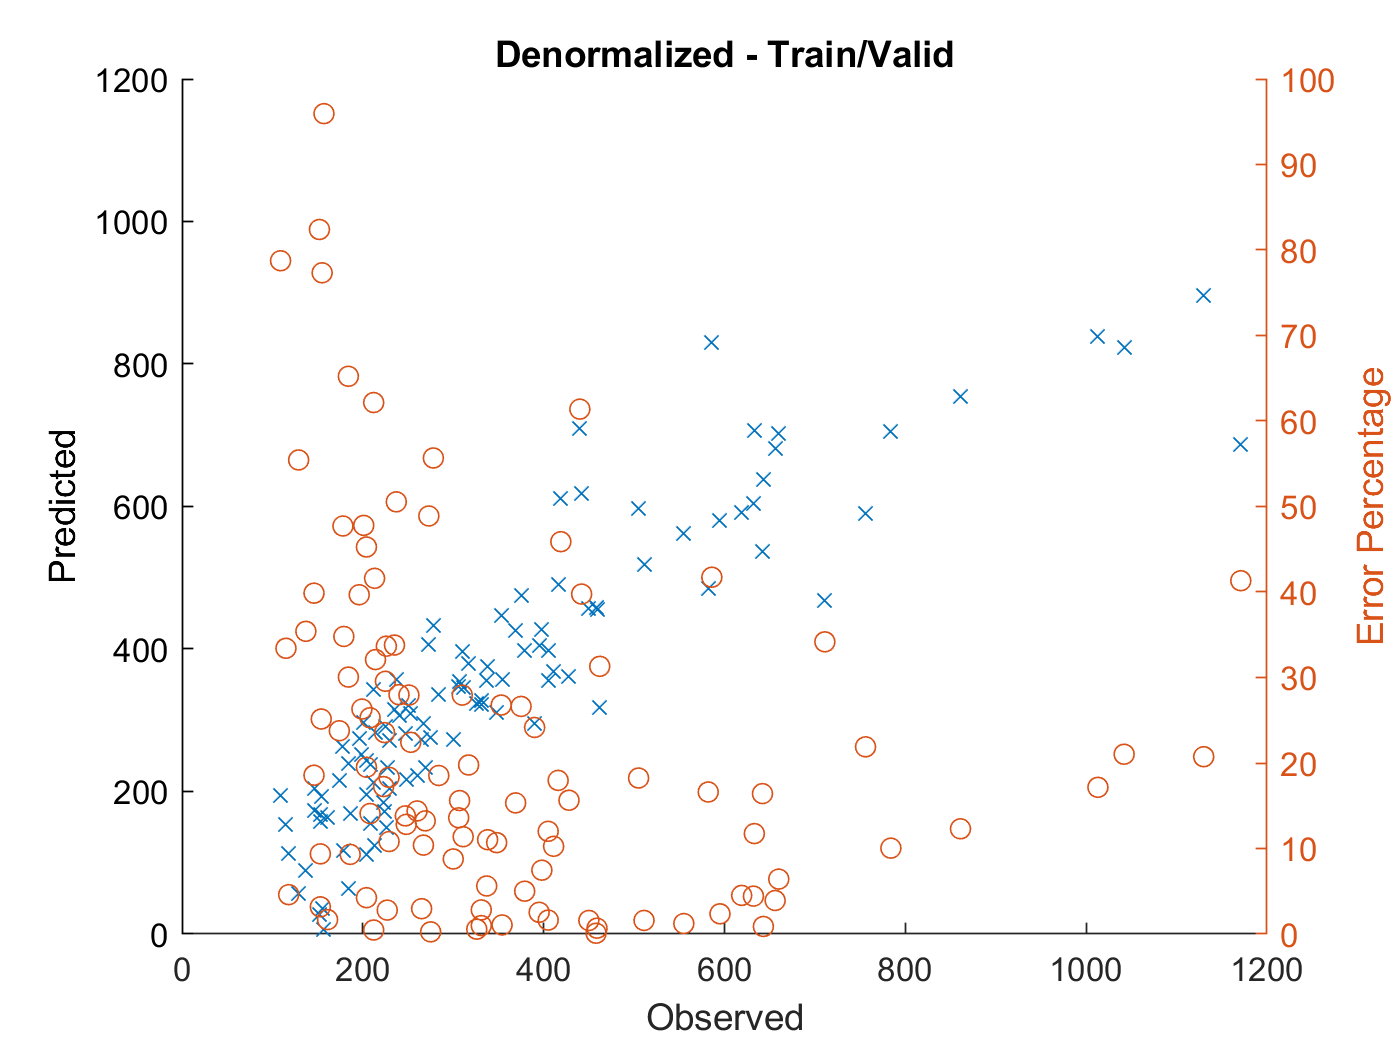


figure
hold on
plot(Y_trainValid_First_RUL,Yfit_trainValid_VdFirst,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_trainValid_First_RUL,Y_trainValid_diff_percentage_VdFirst,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdFirst

RMSE_test_VdFirst = 175.4170

Y_trainValid_diff_percentage_avg_VdFirst

Y_trainValid_diff_percentage_avg_VdFirst = 22.4748

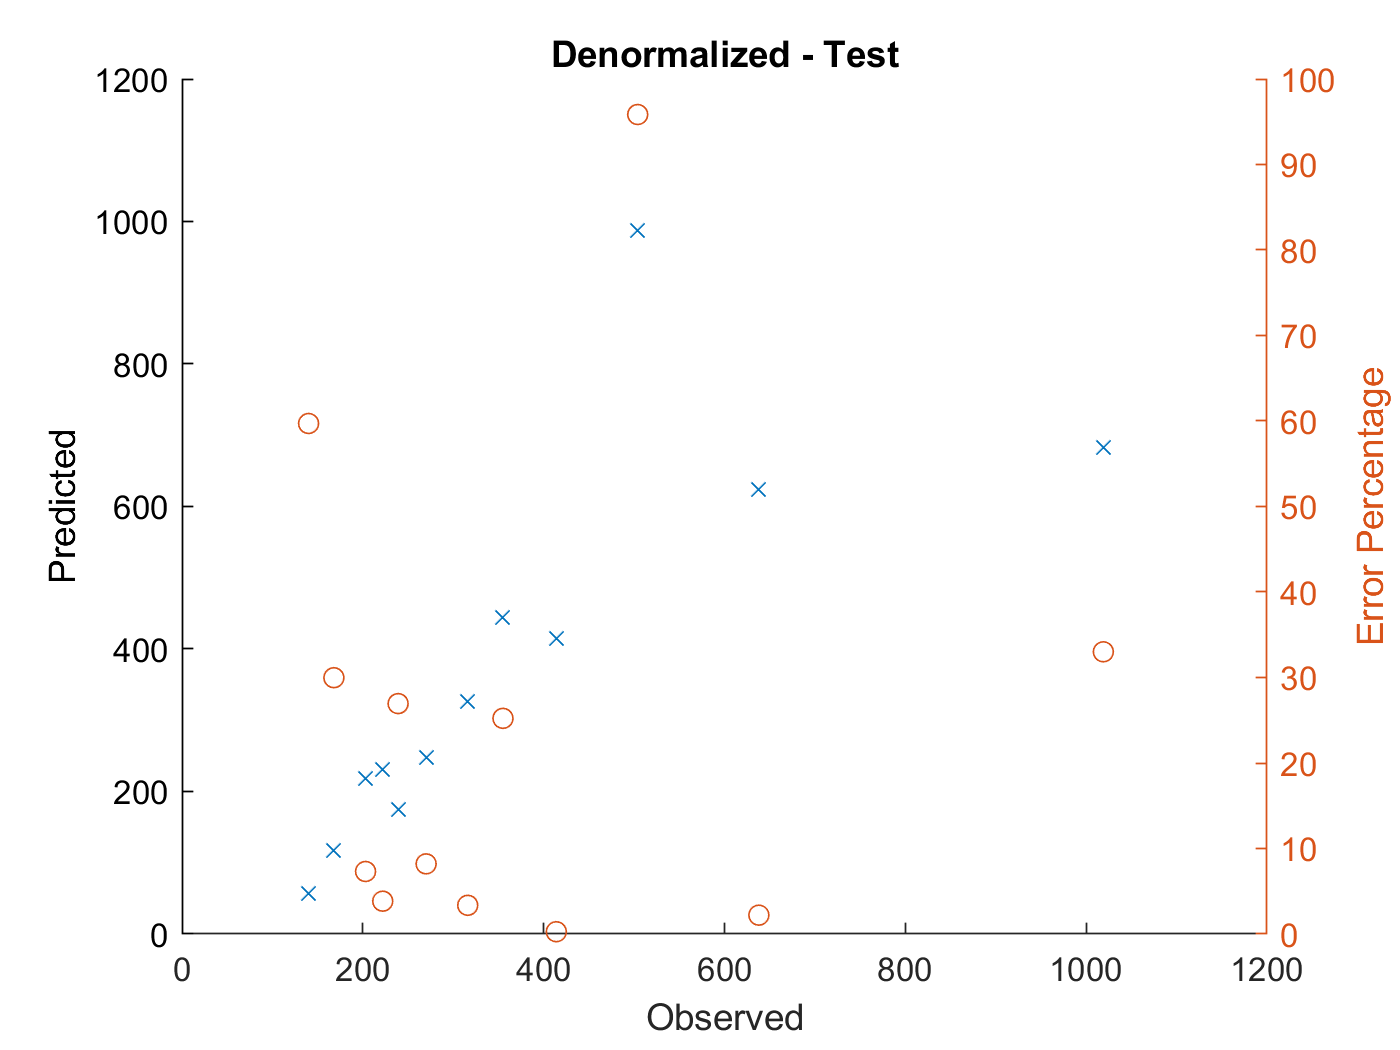


figure
hold on
plot(Y_test_First_RUL,Yfit_test_VdFirst,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_First_RUL,Y_test_diff_percentage_VdFirst,'o');

hold off
title 'Denormalized - Test'